# HW3

clc;clear;close all;
% syms l1 l2 h m1 m2 m_d4 M g theta1 theta2 d4 dtheta1 dtheta2 dd4
% q=[theta1 theta2 d4];
% q_dot=[dtheta1 dtheta2 dd4];
global l2 h m1 m2 m_d4 M g rho d l
rho= 7800;
d=0.015;
l=0.2;
l2=0.2; 
h=0.1; 
g=9.81;
M=0.5;
m1=pi*d^2/4*h*rho;
m2=pi*d^2/4*l2*rho;
m_d4=pi*d^2/4*l*rho; 
para=[m1 m2 m_d4 M g h l2 l ];
q = rand(1,3);
q_dot = rand(1,3);
[H,C,G] = dynamics_mat(q,q_dot,para);
disp(H);disp(C);disp(G);

$$\left(\begin{array}{ccc} \frac{21879348253820579881990915434611854771234467804784423821363011941143322016595025187918860456560399\,\pi }{34175792574734561318320347298712833833643272357706444319152665725155515612490248800367393390985216000}+\frac{16729013521730736332769120777565667593101662855400309097337209569544403490560951224814389129802886722480324779}{300613450595050653169853516389035139504087366260264943450533244356122755214669880763353471793250393988087676928} & \frac{100388386119457072225114173513396033429807430421838914926779086395865626600001468822683667911}{533996758980227520598755426542388028650676130589163192486760401955554931445160137505740521734144} & \frac{1}{144115188075855872}\\ \frac{100388386119457072225114173513396033429807430421838914926779086395865626600001468822683667911}{533996758980227520598755426542388028650676130589163192486760401955554931445160137505740521734144} & \frac{1423825154176347208728709963467291\,\pi }{1622592768292133633915780102881280000}+\frac{525895846269047545854853288009291111938764906685532469847830907893663625808219155}{948568795032094272909893509191171341133987714380927500611236528192824358010355712} & \frac{351\,\pi }{20000}+\frac{1}{10}\\ \frac{1}{144115188075855872} & \frac{351\,\pi }{20000}+\frac{1}{10} & \frac{351\,\pi }{4000}+\frac{1}{2} \end{array}\right)$$

    0.1205    0.1636    0.0932
   -0.1636    0.5928    0.0963
   -0.0932   -0.0963         0

   -1.5237
   -1.6631
   -1.0878



## Q2

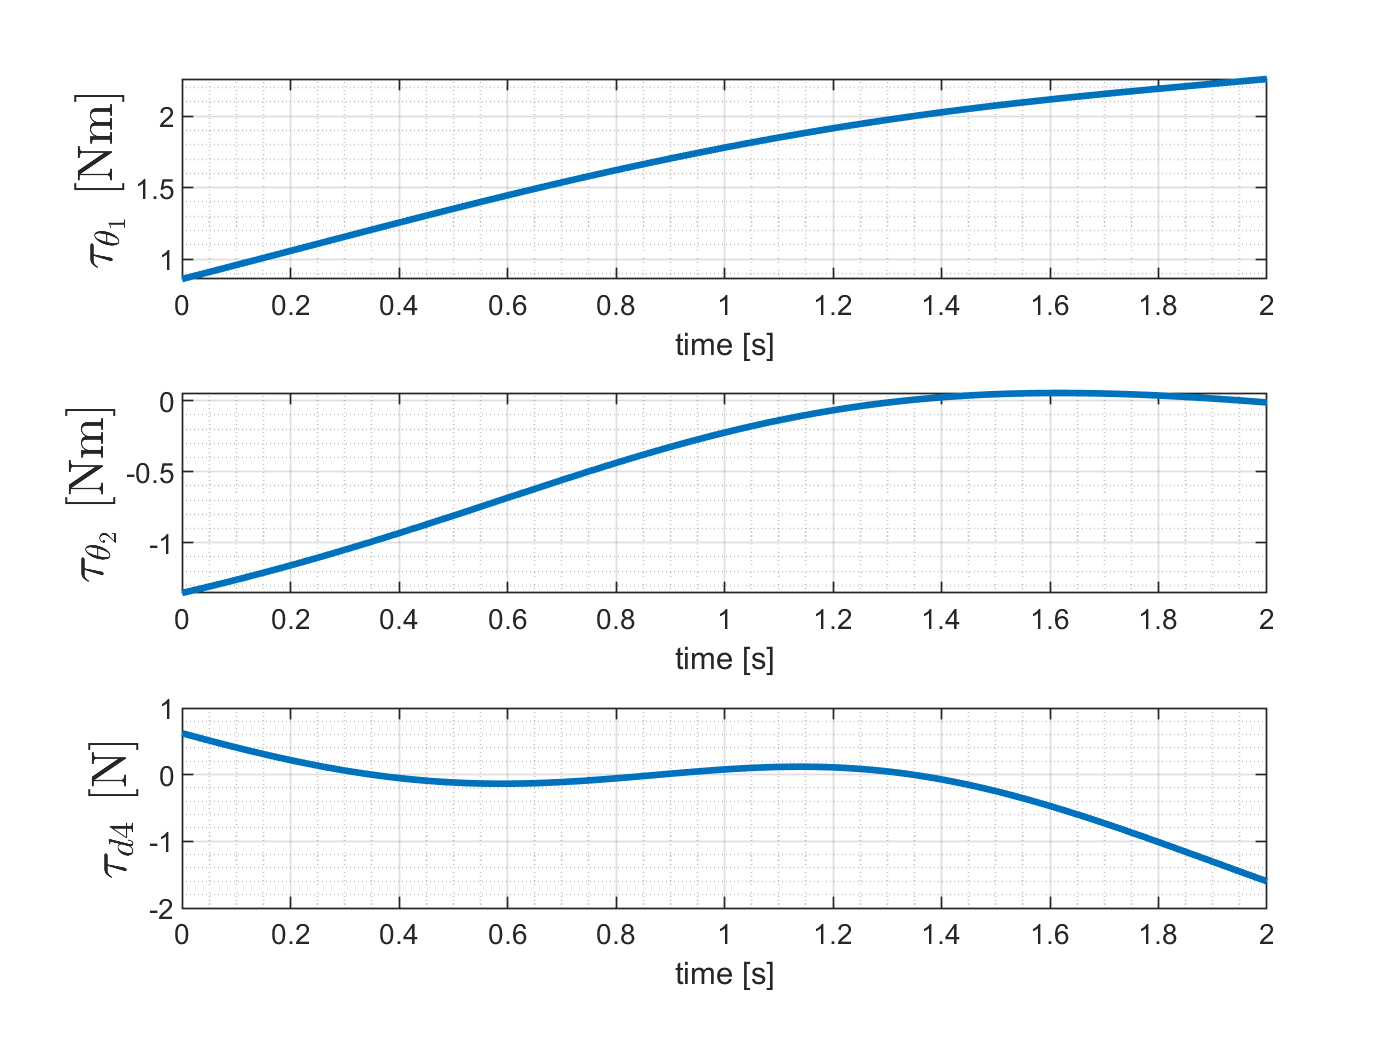

clc;clear;close all;
T = 2;
n = 200;

tao=zeros(3,2000);
tau = tau_plan(T, n);


t = linspace(0, T, n);


figure(1)
subplot(3,1,1)
plot(t,tau(1,:),'linewidth',2)
grid on; grid minor;
xlabel('time [s]')
ylabel('$\tau_{\theta_1}$ [Nm]','interpreter','latex','fontsize',15)
subplot(3,1,2)
plot(t,tau(2,:),'linewidth',2)
grid on; grid minor;
xlabel('time [s]')
ylabel('$\tau_{\theta_2}$ [Nm]','interpreter','latex','fontsize',15)
subplot(3,1,3)
plot(t,tau(3,:),'linewidth',2)
grid on; grid minor;
xlabel('time [s]')
ylabel('$\tau_{d4}$ [N]','interpreter','latex','fontsize',15)
saveas(gcf, 'q2','png')

## Q3

clc;clear;close all;
global l2 l3 h m1 m2 m_d4 M g rho d l
rho= 7800;
d=0.015;
l=0.2;
l2=0.2; 
h=0.1; 
g=9.81;
M=0.5;
m1=pi*d^2/4*h*rho;
m2=pi*d^2/4*l2*rho;
m_d4=pi*d^2/4*l*rho; 
para=[m1 m2 m_d4 M g h l2 l ];

PROFILE = 'constant';
T = 2;
n = 20;
h = 0.1;
l2 = 0.2;
l3 = 0;
params = [h,l2,l3];
x_init = [0.1, 0.2, 0.35]';
x_fin = [0.3, -0.1, 0.15]';
x = x_plan(PROFILE, T, n, x_init, x_fin);
v = v_plan(PROFILE, T, n, x_init, x_fin);
a = a_plan(PROFILE, T, n, x_init, x_fin);

q_ = q_plan(x, [1,1], params)

q_ =     1.1071    1.0304    0.9476    0.8593    0.7665    0.6705    0.5730    0.4757    0.3805    0.2890    0.2023    0.1214    0.0465   -0.0222   -0.0849   -0.1419   -0.1936   -0.2405   -0.2831   -0.3218
   -0.0909   -0.0603   -0.0319   -0.0069    0.0132    0.0267    0.0317    0.0266    0.0097   -0.0201   -0.0631   -0.1185   -0.1847   -0.2591   -0.3390   -0.4217   -0.5046   -0.5860   -0.6645   -0.7392
    0.2693    0.2520    0.2354    0.2198    0.2053    0.1921    0.1806    0.1711    0.1639    0.1593    0.1577    0.1590    0.1632    0.1701    0.1794    0.1907    0.2037    0.2180    0.2336    0.2500


q_dot_ = q_dot_plan(q_, v, T, 'analytical', params);
q_dot2_ = q_dot2_plan(q_, q_dot_, a, T,'analytical', params);

for j=1:1:20
    q = q_(:,j);
    q_dot = q_dot_(:,j);
    q_dot2= q_dot2_(:,j);
   % Forward recursion  
   [omega,alpha,ae,ac] = forward_recursion(q, q_dot, q_dot2,para);
    
   % Backward recursion
    [f] = backward_recursion(ac,ae,q,para);
     [Mo] = backward_recursion_M(ac,ae,q,para,alpha,omega);
   f3(:,j)=f(:,4);
   f2(:,j)=f(:,3);
   M2(:,j)=Mo(:,3);
   M1(:,j)=Mo(:,2);
end
f3

f3 =     0.2919    0.2391    0.1682    0.0841   -0.0047   -0.0848   -0.1395   -0.1492   -0.0951    0.0379    0.2563    0.5546    0.9153    1.3128    1.7198    2.1129    2.4749    2.7958    3.0717    3.3026
    0.3931    0.2428    0.1119    0.0082   -0.0613   -0.0929   -0.0875   -0.0518    0.0018    0.0570    0.0963    0.1041    0.0700   -0.0097   -0.1324   -0.2907   -0.4747   -0.6744   -0.8807   -1.0861
    4.8651    4.8827    4.8998    4.9180    4.9391    4.9646    4.9949    5.0289    5.0630    5.0909    5.1039    5.0919    5.0459    4.9600    4.8326    4.6660    4.4661    4.2403    3.9968    3.7432


f2

f2 =     0.0600    0.0920    0.1002    0.0858    0.0532    0.0107   -0.0299   -0.0541   -0.0471    0.0034    0.1034    0.2501    0.4316    0.6306    0.8293    1.0134    1.1734    1.3052    1.4080    1.4840
    0.3931    0.2428    0.1119    0.0082   -0.0613   -0.0929   -0.0875   -0.0518    0.0018    0.0570    0.0963    0.1041    0.0700   -0.0097   -0.1324   -0.2907   -0.4747   -0.6744   -0.8807   -1.0861
    7.5428    7.5672    7.5891    7.6109    7.6352    7.6641    7.6986    7.7375    7.7764    7.8070    7.8171    7.7925    7.7197    7.5891    7.3972    7.1467    6.8454    6.5043    6.1354    5.7504


M2

M2 =     0.0785    0.0484    0.0222    0.0015   -0.0124   -0.0187   -0.0175   -0.0103    0.0005    0.0117    0.0196    0.0211    0.0143   -0.0017   -0.0263   -0.0580   -0.0948   -0.1348   -0.1761   -0.2173
   -0.0351   -0.0330   -0.0266   -0.0166   -0.0043    0.0081    0.0178    0.0213    0.0153   -0.0030   -0.0350   -0.0796   -0.1341   -0.1940   -0.2548   -0.3127   -0.3650   -0.4104   -0.4484   -0.4791
         0         0         0         0         0   -0.0000   -0.0000         0   -0.0000         0         0         0         0         0         0         0         0         0         0         0


M1

M1 =     0.0785    0.0484    0.0222    0.0015   -0.0124   -0.0187   -0.0175   -0.0103    0.0005    0.0117    0.0196    0.0211    0.0143   -0.0017   -0.0263   -0.0580   -0.0948   -0.1348   -0.1761   -0.2173
    1.7422    1.7499    1.7611    1.7756    1.7929    1.8112    1.8279    1.8393    1.8413    1.8291    1.7988    1.7479    1.6762    1.5858    1.4802    1.3638    1.2412    1.1161    0.9919    0.8711
   -0.0786   -0.0486   -0.0224   -0.0016    0.0123    0.0186    0.0175    0.0104   -0.0004   -0.0114   -0.0193   -0.0208   -0.0140    0.0019    0.0265    0.0581    0.0949    0.1349    0.1761    0.2172


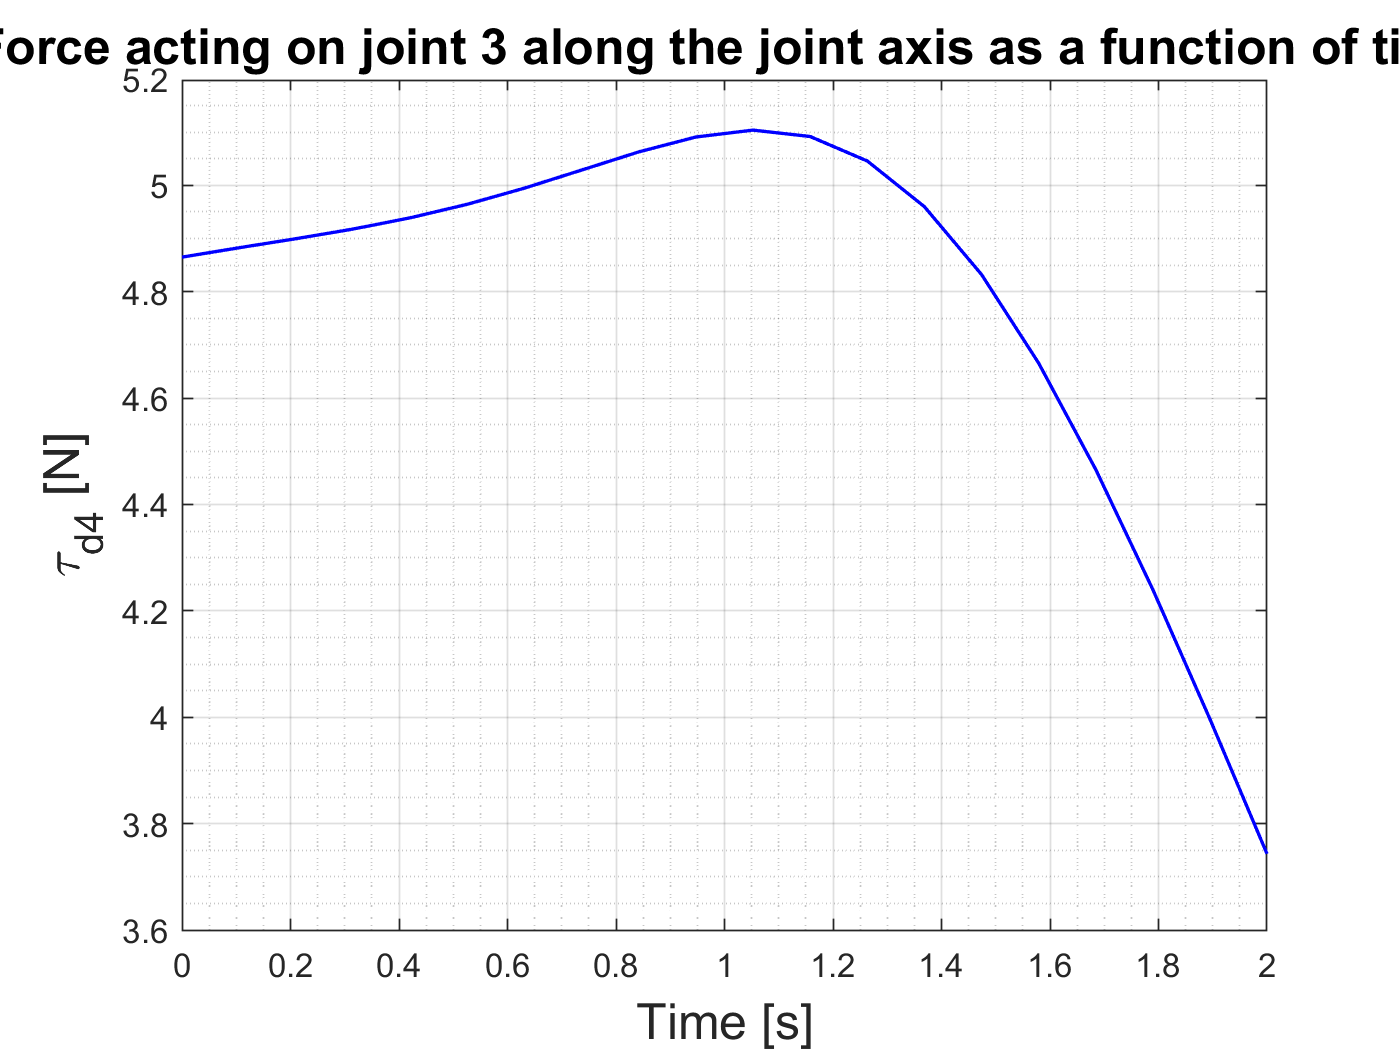

t = linspace(0, T, n);
plot(t,f3(3,:),'b-','linewidth',1)
grid on; grid minor;
xlabel('Time [s]','interpreter','tex','fontsize',15)
ylabel('\tau_{d4} [N]','interpreter','tex','fontsize',15)
title('Force acting on joint 3 along the joint axis as a function of time','fontsize',15)
saveas(gcf, 'q3','png')

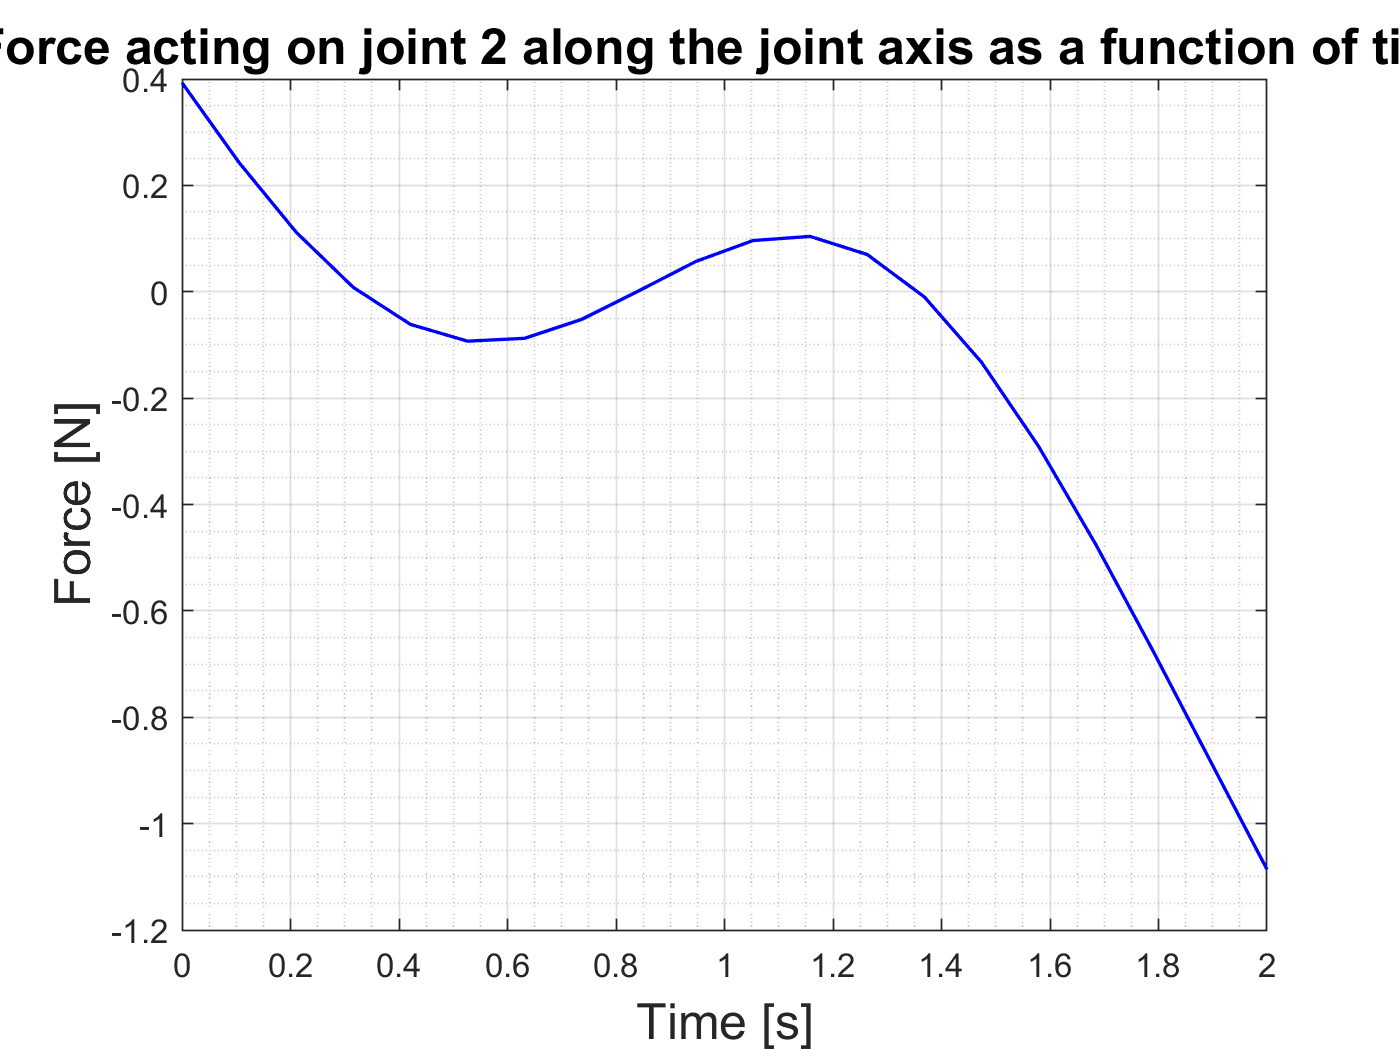


plot(t,f2(2,:),'b-','linewidth',1)
grid on; grid minor;
xlabel('Time [s]','interpreter','tex','fontsize',15)
ylabel('Force [N]','interpreter','tex','fontsize',15)
title('Force acting on joint 2 along the joint axis as a function of time','fontsize',15)
saveas(gcf, 'q3','png')

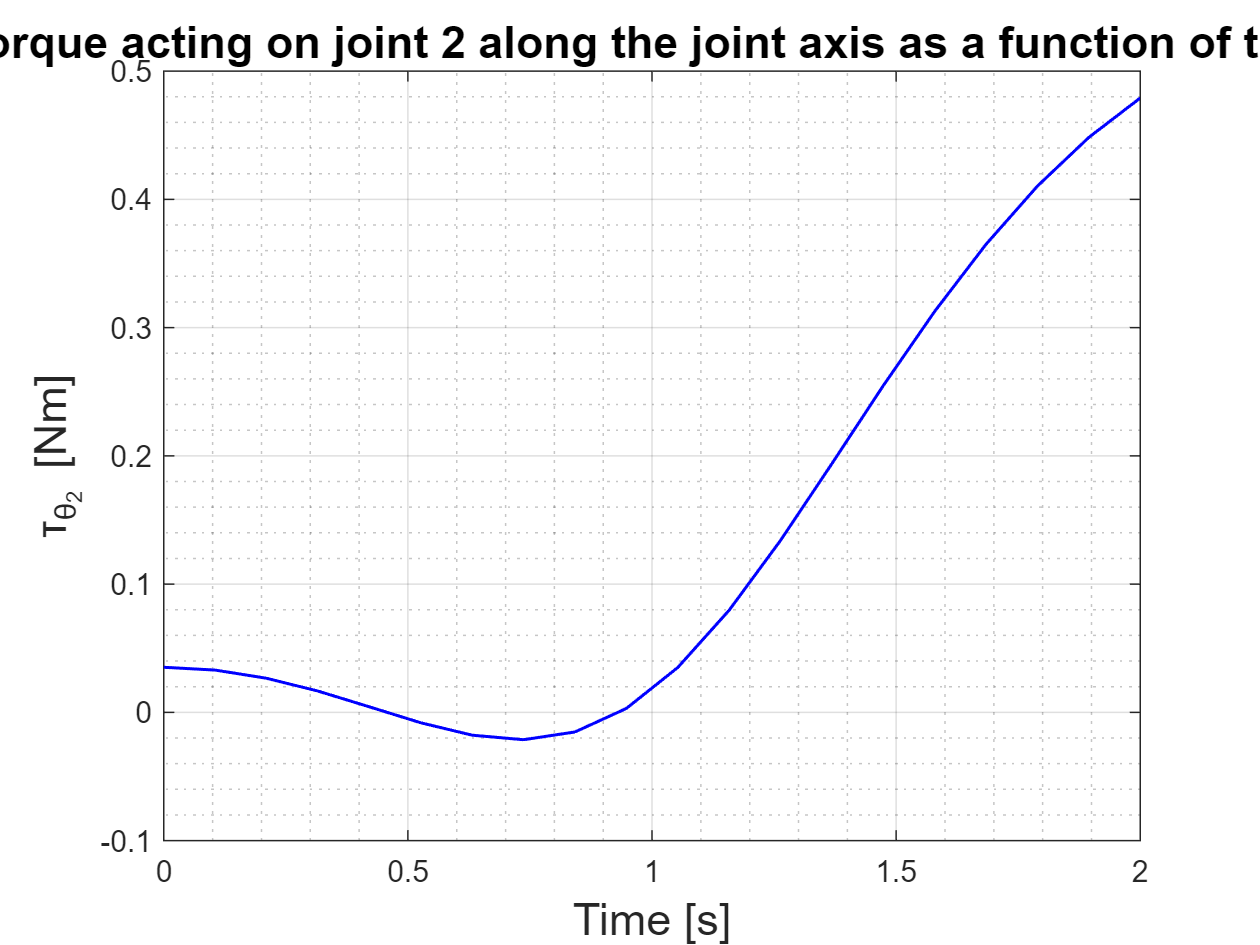


t = linspace(0, T, n);
plot(t,-M2(2,:),'b-','linewidth',1)
grid on; grid minor;
xlabel('Time [s]','interpreter','tex','fontsize',15)
ylabel('\tau_{\theta_2} [Nm]','interpreter','tex','fontsize',15)
title('torque acting on joint 2 along the joint axis as a function of time','fontsize',15)
saveas(gcf, 'q3','png')

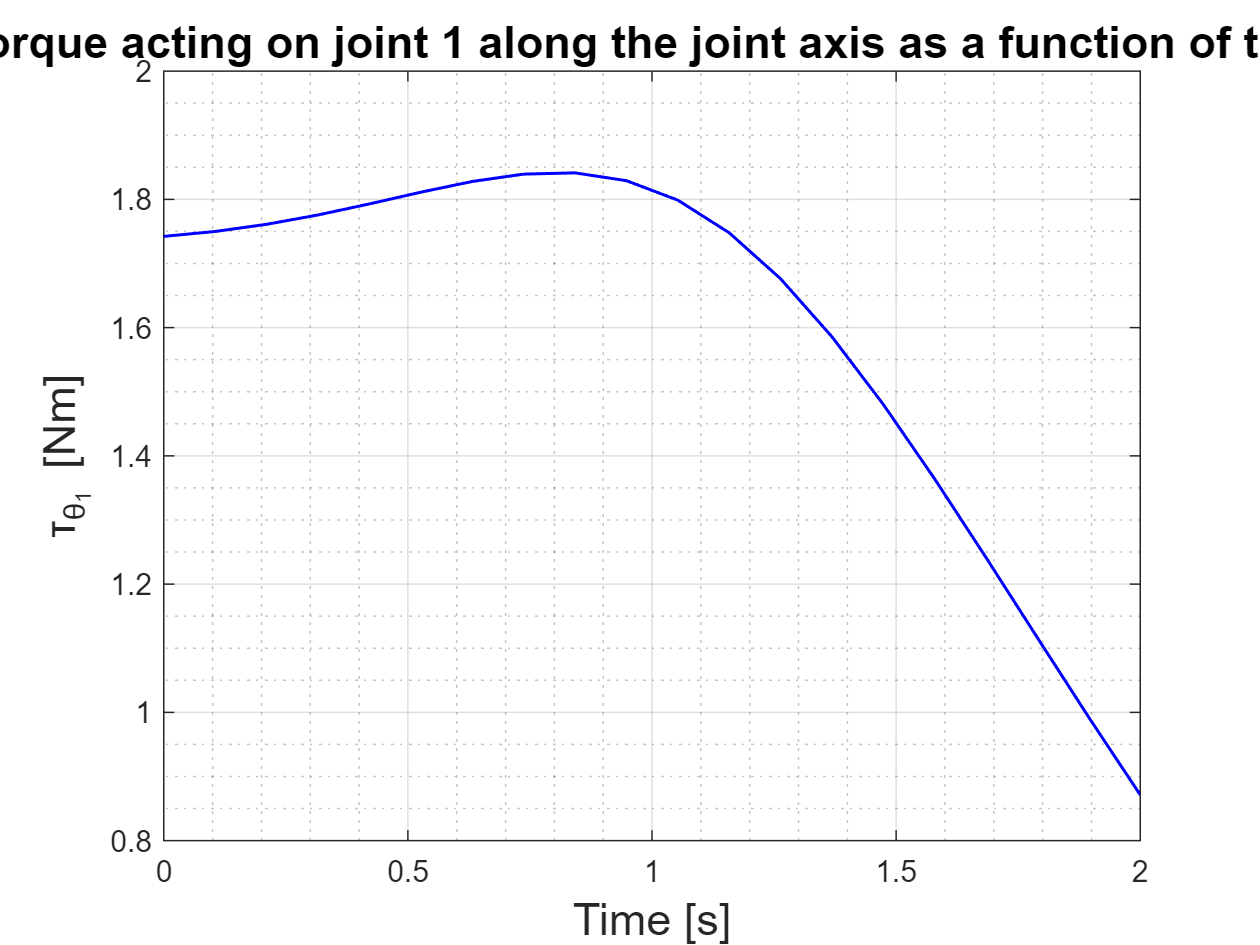


t = linspace(0, T, n);
plot(t,M1(2,:),'b-','linewidth',1)
grid on; grid minor;
xlabel('Time [s]','interpreter','tex','fontsize',15)
ylabel('\tau_{\theta_1} [Nm]','interpreter','tex','fontsize',15)
title('torque acting on joint 1 along the joint axis as a function of time','fontsize',15)
saveas(gcf, 'q3','png')

## **Q4**

T = 2;
n = 2001;
tau = tau_plan(T, n);
size(tau)

ans =            3        2001


global counter;
counter = 1;
% syms q1 q2 q3 qdot1 qdot2 qdot3
% qs = [q1 q2 q3];
% qdots = [qdot1 qdot2 qdot3];
% X = [qs qdots]
tspan=0:0.0001:2;
X0 = [q_(:,1)',0, 0, 0] %X0 = [q_(:,1)',q_dot_(:,1)']

X0 =     1.1071   -0.0909    0.2693         0         0         0


[t_reg,X] = ode45(@state_eq, tspan, X0);

index = 1

counter = 1

X_dot =          0
         0
         0
   -0.1363
   -0.0096
    0.0080


index = 1

counter = 2

X_dot =    -0.0000
   -0.0000
    0.0000
   -0.1363
   -0.0096
    0.0080


index = 1

counter = 3

X_dot =    -0.0000
   -0.0000
    0.0000
   -0.1363
   -0.0096
    0.0080


index = 1

counter = 4

X_dot =    -0.0000
   -0.0000
    0.0000
   -0.1363
   -0.0096
    0.0080


index = 1

counter = 5

X_dot =    -0.0000
   -0.0000
    0.0000
   -0.1363
   -0.0096
    0.0080


index = 1

counter = 6

X_dot =    -0.0000
   -0.0000
    0.0000
   -0.1363
   -0.0096
    0.0080


index = 1

counter = 7

X_dot =    -0.0000
   -0.0000
    0.0000
   -0.1363
   -0.0096
    0.0080


index = 1

counter = 8

X_dot =    -0.0000
   -0.0000
    0.0000
   -0.1363
   -0.0096
    0.0080


index = 1

counter = 9

X_dot =    -0.0000
   -0.0000
    0.0000
   -0.1363
   -0.0096
    0.0080


index = 1

counter = 10

X_dot =    -0.0001
   -0.0000
    0.0000
   -0.1363
   -0.0096
    0.0080


index = 1

counter = 11

X_dot =    -0.0001
   -0.0000
    0.0000
   -0.1363
   -0.0096
    0.0080


index = 1

counter = 12

X_dot =    -0.0001
   -0.0000
    0.0000
   -0.1363
   -0.0096
    0.0080


index = 1

counter = 13

X_dot =    -0.0001
   -0.0000
    0.0000
   -0.1363
   -0.0096
    0.0080


index = 2

counter = 14

X_dot =    -0.0001
   -0.0000
    0.0000
   -0.1103
    0.0203
   -0.0010


index = 2

counter = 15

X_dot =    -0.0002
    0.0000
    0.0000
   -0.1103
    0.0203
   -0.0010


index = 3

counter = 16

X_dot =    -0.0004
   -0.0000
    0.0000
   -0.0886
    0.0505
   -0.0098


index = 3

counter = 17

X_dot =    -0.0005
   -0.0002
    0.0001
   -0.0886
    0.0505
   -0.0098


index = 4

counter = 18

X_dot =    -0.0005
   -0.0002
    0.0001
   -0.0657
    0.0799
   -0.0185


index = 4

counter = 19

X_dot =    -0.0003
    0.0001
   -0.0000
   -0.0657
    0.0799
   -0.0185


index = 1

counter = 20

X_dot =    -0.0001
   -0.0000
    0.0000
   -0.1363
   -0.0096
    0.0080


index = 2

counter = 21

X_dot =    -0.0002
   -0.0000
    0.0000
   -0.1103
    0.0203
   -0.0010


index = 3

counter = 22

X_dot =    -0.0001
    0.0002
   -0.0000
   -0.0886
    0.0505
   -0.0098


index = 3

counter = 23

X_dot =     0.0001
    0.0005
   -0.0001
   -0.0886
    0.0505
   -0.0098


index = 3

counter = 24

X_dot =     0.0001
    0.0005
   -0.0001
   -0.0886
    0.0505
   -0.0098


index = 3

counter = 25

X_dot =    -0.0003
    0.0001
   -0.0000
   -0.0886
    0.0505
   -0.0098


index = 3

counter = 26

X_dot =    -0.0003
    0.0001
   -0.0000
   -0.0886
    0.0505
   -0.0098


index = 4

counter = 27

X_dot =    -0.0003
    0.0001
   -0.0000
   -0.0657
    0.0799
   -0.0185


index = 4

counter = 28

X_dot =    -0.0003
    0.0003
   -0.0001
   -0.0657
    0.0799
   -0.0185


index = 5

counter = 29

X_dot =    -0.0000
    0.0007
   -0.0002
   -0.0411
    0.1098
   -0.0274


index = 5

counter = 30

X_dot =    -0.0001
    0.0006
   -0.0002
   -0.0411
    0.1098
   -0.0274


index = 5

counter = 31

X_dot =    -0.0004
    0.0002
   -0.0000
   -0.0411
    0.1098
   -0.0274


index = 3

counter = 32

X_dot =    -0.0003
    0.0001
   -0.0000
   -0.0886
    0.0505
   -0.0098


index = 3

counter = 33

X_dot =    -0.0003
    0.0001
   -0.0000
   -0.0886
    0.0505
   -0.0098


index = 4

counter = 34

X_dot =    -0.0004
    0.0001
   -0.0000
   -0.0657
    0.0799
   -0.0185


index = 4

counter = 35

X_dot =    -0.0004
    0.0001
   -0.0000
   -0.0657
    0.0799
   -0.0185


index = 4

counter = 36

X_dot =    -0.0004
    0.0001
   -0.0000
   -0.0657
    0.0799
   -0.0185


index = 4

counter = 37

X_dot =    -0.0004
    0.0001
   -0.0000
   -0.0657
    0.0799
   -0.0185


index = 5

counter = 38

X_dot =    -0.0004
    0.0002
   -0.0000
   -0.0411
    0.1098
   -0.0274


index = 5

counter = 39

X_dot =    -0.0004
    0.0002
   -0.0000
   -0.0411
    0.1098
   -0.0274


index = 5

counter = 40

X_dot =    -0.0005
    0.0002
   -0.0000
   -0.0411
    0.1098
   -0.0274


index = 5

counter = 41

X_dot =    -0.0005
    0.0001
   -0.0000
   -0.0411
    0.1098
   -0.0274


index = 6

counter = 42

X_dot =    -0.0005
    0.0002
   -0.0000
   -0.0151
    0.1397
   -0.0363


index = 6

counter = 43

X_dot =    -0.0004
    0.0003
   -0.0001
   -0.0151
    0.1397
   -0.0363


index = 6

counter = 44

X_dot = 6×1
   -0.0004
    0.0003
   -0.0001
   -0.0151
    0.1397
   -0.0363


index = 6

counter = 45

X_dot = 6×1
   -0.0004
    0.0003
   -0.0001
   -0.0151
    0.1397
   -0.0363


index = 7

counter = 46

X_dot = 6×1
   -0.0004
    0.0004
   -0.0001
    0.0066
    0.1699
   -0.0452


index = 7

counter = 47

X_dot = 6×1
   -0.0005
    0.0004
   -0.0001
    0.0066
    0.1699
   -0.0451


index = 7

counter = 48

X_dot = 6×1
   -0.0004
    0.0004
   -0.0001
    0.0066
    0.1699
   -0.0451


index = 7

counter = 49

X_dot = 6×1
   -0.0004
    0.0005
   -0.0001
    0.0066
    0.1699
   -0.0451


index = 7

counter = 50

X_dot = 6×1
   -0.0004
    0.0005
   -0.0001
    0.0066
    0.1699
   -0.0451


index = 7

counter = 51

X_dot = 6×1
   -0.0004
    0.0005
   -0.0001
    0.0066
    0.1699
   -0.0451


index = 8

counter = 52

X_dot = 6×1
   -0.0004
    0.0007
   -0.0002
    0.0312
    0.1993
   -0.0539


index = 8

counter = 53

X_dot = 6×1
   -0.0004
    0.0007
   -0.0002
    0.0312
    0.1993
   -0.0539


index = 8

counter = 54

X_dot = 6×1
   -0.0004
    0.0007
   -0.0002
    0.0312
    0.1993
   -0.0539


index = 8

counter = 55

X_dot = 6×1
   -0.0004
    0.0007
   -0.0002
    0.0312
    0.1993
   -0.0539


index = 9

counter = 56

X_dot = 6×1
   -0.0004
    0.0008
   -0.0002
    0.0541
    0.2292
   -0.0627


index = 9

counter = 57

X_dot = 6×1
   -0.0004
    0.0008
   -0.0002
    0.0541
    0.2292
   -0.0627


index = 10

counter = 58

X_dot = 6×1
   -0.0004
    0.0010
   -0.0002
    0.0776
    0.2586
   -0.0715


index = 10

counter = 59

X_dot = 6×1
   -0.0005
    0.0009
   -0.0002
    0.0777
    0.2585
   -0.0715


index = 10

counter = 60

X_dot = 6×1
   -0.0004
    0.0010
   -0.0002
    0.0777
    0.2585
   -0.0715


index = 10

counter = 61

X_dot = 6×1
   -0.0003
    0.0011
   -0.0003
    0.0776
    0.2585
   -0.0715


index = 10

counter = 62

X_dot = 6×1
   -0.0003
    0.0013
   -0.0003
    0.0777
    0.2585
   -0.0715


index = 11

counter = 63

X_dot = 6×1
   -0.0002
    0.0013
   -0.0003
    0.1019
    0.2892
   -0.0805


index = 12

counter = 64

X_dot = 6×1
    0.0000
    0.0019
   -0.0005
    0.1265
    0.3186
   -0.0892


index = 12

counter = 65

X_dot = 6×1
    0.0004
    0.0023
   -0.0006
    0.1265
    0.3186
   -0.0892


index = 12

counter = 66

X_dot = 6×1
    0.0004
    0.0024
   -0.0006
    0.1265
    0.3186
   -0.0892


index = 12

counter = 67

X_dot = 6×1
   -0.0000
    0.0018
   -0.0005
    0.1265
    0.3186
   -0.0892


index = 13

counter = 68

X_dot = 6×1
    0.0000
    0.0020
   -0.0005
    0.1512
    0.3484
   -0.0981


index = 13

counter = 69

X_dot = 6×1
    0.0001
    0.0021
   -0.0006
    0.1512
    0.3484
   -0.0980


index = 15

counter = 70

X_dot = 6×1
    0.0002
    0.0026
   -0.0007
    0.1973
    0.4080
   -0.1156


index = 15

counter = 71

X_dot = 6×1
    0.0001
    0.0024
   -0.0006
    0.1973
    0.4080
   -0.1156


index = 15

counter = 72

X_dot = 6×1
    0.0002
    0.0026
   -0.0007
    0.1974
    0.4080
   -0.1155


index = 15

counter = 73

X_dot = 6×1
    0.0005
    0.0029
   -0.0008
    0.1973
    0.4080
   -0.1156


index = 16

counter = 74

X_dot = 6×1
    0.0006
    0.0032
   -0.0009
    0.2220
    0.4374
   -0.1243


index = 16

counter = 75

X_dot = 6×1
    0.0006
    0.0033
   -0.0009
    0.2220
    0.4373
   -0.1243


index = 18

counter = 76

X_dot = 6×1
    0.0009
    0.0039
   -0.0011
    0.2704
    0.4972
   -0.1420


index = 18

counter = 77

X_dot = 6×1
    0.0008
    0.0038
   -0.0010
    0.2704
    0.4972
   -0.1419


index = 18

counter = 78

X_dot = 6×1
    0.0009
    0.0040
   -0.0011
    0.2705
    0.4971
   -0.1419


index = 18

counter = 79

X_dot = 6×1
    0.0012
    0.0043
   -0.0012
    0.2704
    0.4972
   -0.1419


index = 19

counter = 80

X_dot = 6×1
    0.0013
    0.0046
   -0.0013
    0.2948
    0.5267
   -0.1506


index = 19

counter = 81

X_dot = 6×1
    0.0014
    0.0048
   -0.0013
    0.2948
    0.5267
   -0.1506


index = 21

counter = 82

X_dot = 6×1
    0.0018
    0.0055
   -0.0015
    0.3402
    0.5858
   -0.1681


index = 21

counter = 83

X_dot = 6×1
    0.0017
    0.0054
   -0.0015
    0.3402
    0.5858
   -0.1680


index = 21

counter = 84

X_dot = 6×1
    0.0019
    0.0056
   -0.0016
    0.3403
    0.5858
   -0.1680


index = 21

counter = 85

X_dot = 6×1
    0.0021
    0.0060
   -0.0017
    0.3403
    0.5858
   -0.1680


index = 22

counter = 86

X_dot = 6×1
    0.0024
    0.0064
   -0.0018
    0.3646
    0.6155
   -0.1767


index = 22

counter = 87

X_dot = 6×1
    0.0025
    0.0066
   -0.0018
    0.3647
    0.6154
   -0.1767


index = 24

counter = 88

X_dot = 6×1
    0.0031
    0.0076
   -0.0021
    0.4134
    0.6745
   -0.1941


index = 24

counter = 89

X_dot = 6×1
    0.0030
    0.0075
   -0.0021
    0.4135
    0.6745
   -0.1941


index = 25

counter = 90

X_dot = 6×1
    0.0032
    0.0078
   -0.0022
    0.4366
    0.7066
   -0.2033


index = 25

counter = 91

X_dot = 6×1
    0.0035
    0.0082
   -0.0023
    0.4365
    0.7066
   -0.2033


index = 25

counter = 92

X_dot = 6×1
    0.0038
    0.0087
   -0.0024
    0.4367
    0.7065
   -0.2033


index = 26

counter = 93

X_dot = 6×1
    0.0039
    0.0089
   -0.0025
    0.4611
    0.7362
   -0.2120


index = 27

counter = 94

X_dot = 6×1
    0.0049
    0.0104
   -0.0029
    0.4877
    0.7659
   -0.2206


index = 28

counter = 95

X_dot = 6×1
    0.0054
    0.0111
   -0.0031
    0.5100
    0.7948
   -0.2292


index = 28

counter = 96

X_dot = 6×1
    0.0056
    0.0113
   -0.0032
    0.5102
    0.7947
   -0.2291


index = 28

counter = 97

X_dot = 6×1
    0.0050
    0.0106
   -0.0030
    0.5102
    0.7947
   -0.2291


index = 28

counter = 98

X_dot = 6×1
    0.0053
    0.0111
   -0.0031
    0.5104
    0.7946
   -0.2290


index = 29

counter = 99

X_dot = 6×1
    0.0054
    0.0113
   -0.0032
    0.5352
    0.8251
   -0.2380


index = 30

counter = 100

X_dot = 6×1
    0.0065
    0.0128
   -0.0036
    0.5585
    0.8540
   -0.2464


index = 31

counter = 101

X_dot = 6×1
    0.0070
    0.0136
   -0.0039
    0.5846
    0.8839
   -0.2552


index = 31

counter = 102

X_dot = 6×1
    0.0072
    0.0138
   -0.0039
    0.5848
    0.8838
   -0.2551


index = 31

counter = 103

X_dot = 6×1
    0.0066
    0.0131
   -0.0037
    0.5848
    0.8838
   -0.2551


index = 31

counter = 104

X_dot = 6×1
    0.0069
    0.0136
   -0.0039
    0.5852
    0.8837
   -0.2550


index = 32

counter = 105

X_dot = 6×1
    0.0071
    0.0139
   -0.0039
    0.6075
    0.9152
   -0.2642


index = 33

counter = 106

X_dot = 6×1
    0.0082
    0.0155
   -0.0044
    0.6331
    0.9451
   -0.2727


index = 33

counter = 107

X_dot = 6×1
    0.0087
    0.0162
   -0.0046
    0.6333
    0.9450
   -0.2726


index = 34

counter = 108

X_dot = 6×1
    0.0089
    0.0165
   -0.0047
    0.6578
    0.9743
   -0.2812


index = 34

counter = 109

X_dot = 6×1
    0.0084
    0.0158
   -0.0045
    0.6578
    0.9743
   -0.2812


index = 34

counter = 110

X_dot = 6×1
    0.0089
    0.0165
   -0.0047
    0.6583
    0.9741
   -0.2811


index = 35

counter = 111

X_dot = 6×1
    0.0091
    0.0168
   -0.0048
    0.6828
    1.0037
   -0.2898


index = 37

counter = 112

X_dot = 6×1
    0.0105
    0.0188
   -0.0054
    0.7310
    1.0629
   -0.3070


index = 37

counter = 113

X_dot = 6×1
    0.0111
    0.0196
   -0.0056
    0.7313
    1.0628
   -0.3070


index = 37

counter = 114

X_dot = 6×1
    0.0114
    0.0200
   -0.0057
    0.7316
    1.0628
   -0.3069


index = 37

counter = 115

X_dot = 6×1
    0.0108
    0.0193
   -0.0055
    0.7316
    1.0627
   -0.3069


index = 38

counter = 116

X_dot = 6×1
    0.0116
    0.0204
   -0.0058
    0.7568
    1.0940
   -0.3157


index = 39

counter = 117

X_dot = 6×1
    0.0120
    0.0210
   -0.0060
    0.7796
    1.1235
   -0.3244


index = 41

counter = 118

X_dot = 6×1
    0.0143
    0.0243
   -0.0070
    0.8314
    1.1824
   -0.3412


index = 42

counter = 119

X_dot = 6×1
    0.0150
    0.0253
   -0.0073
    0.8562
    1.2134
   -0.3500


index = 42

counter = 120

X_dot = 6×1
    0.0154
    0.0259
   -0.0074
    0.8569
    1.2132
   -0.3498


index = 42

counter = 121

X_dot = 6×1
    0.0150
    0.0253
   -0.0072
    0.8568
    1.2131
   -0.3498


index = 44

counter = 122

X_dot = 6×1
    0.0159
    0.0266
   -0.0076
    0.9072
    1.2744
   -0.3675


index = 44

counter = 123

X_dot = 6×1
    0.0165
    0.0274
   -0.0078
    0.9080
    1.2742
   -0.3674


index = 47

counter = 124

X_dot = 6×1
    0.0187
    0.0306
   -0.0088
    0.9814
    1.3631
   -0.3927


index = 47

counter = 125

X_dot = 6×1
    0.0185
    0.0304
   -0.0087
    0.9822
    1.3628
   -0.3925


index = 48

counter = 126

X_dot = 6×1
    0.0192
    0.0314
   -0.0090
    1.0093
    1.3932
   -0.4012


index = 48

counter = 127

X_dot = 6×1
    0.0202
    0.0326
   -0.0093
    1.0092
    1.3933
   -0.4013


index = 49

counter = 128

X_dot = 6×1
    0.0215
    0.0343
   -0.0098
    1.0356
    1.4215
   -0.4092


index = 50

counter = 129

X_dot = 6×1
    0.0221
    0.0353
   -0.0101
    1.0614
    1.4530
   -0.4180


index = 53

counter = 130

X_dot = 6×1
    0.0259
    0.0403
   -0.0116
    1.1385
    1.5429
   -0.4433


index = 54

counter = 131

X_dot = 6×1
    0.0270
    0.0418
   -0.0120
    1.1645
    1.5720
   -0.4516


index = 54

counter = 132

X_dot = 6×1
    0.0277
    0.0429
   -0.0123
    1.1659
    1.5717
   -0.4513


index = 54

counter = 133

X_dot = 6×1
    0.0271
    0.0420
   -0.0120
    1.1658
    1.5717
   -0.4513


index = 56

counter = 134

X_dot = 6×1
    0.0288
    0.0443
   -0.0127
    1.2143
    1.6329
   -0.4686


index = 57

counter = 135

X_dot = 6×1
    0.0298
    0.0456
   -0.0131
    1.2418
    1.6614
   -0.4766


index = 60

counter = 136

X_dot = 6×1
    0.0346
    0.0519
   -0.0149
    1.3231
    1.7509
   -0.5012


index = 61

counter = 137

X_dot = 6×1
    0.0357
    0.0532
   -0.0152
    1.3490
    1.7817
   -0.5097


index = 62

counter = 138

X_dot = 6×1
    0.0368
    0.0545
   -0.0156
    1.3761
    1.8115
   -0.5179


index = 62

counter = 139

X_dot = 6×1
    0.0364
    0.0544
   -0.0156
    1.3759
    1.8116
   -0.5180


index = 64

counter = 140

X_dot = 6×1
    0.0393
    0.0583
   -0.0167
    1.4316
    1.8714
   -0.5344


index = 65

counter = 141

X_dot = 6×1
    0.0409
    0.0603
   -0.0173
    1.4572
    1.8995
   -0.5420


index = 70

counter = 142

X_dot = 6×1
    0.0489
    0.0707
   -0.0202
    1.5984
    2.0512
   -0.5829


index = 71

counter = 143

X_dot = 6×1
    0.0503
    0.0725
   -0.0208
    1.6255
    2.0802
   -0.5907


index = 72

counter = 144

X_dot = 6×1
    0.0522
    0.0750
   -0.0215
    1.6548
    2.1083
   -0.5982


index = 72

counter = 145

X_dot = 6×1
    0.0524
    0.0751
   -0.0215
    1.6543
    2.1084
   -0.5983


index = 76

counter = 146

X_dot = 6×1
    0.0583
    0.0826
   -0.0236
    1.7673
    2.2303
   -0.6309


index = 78

counter = 147

X_dot = 6×1
    0.0617
    0.0869
   -0.0248
    1.8222
    2.2910
   -0.6469


index = 87

counter = 148

X_dot = 6×1
    0.0791
    0.1086
   -0.0309
    2.0937
    2.5606
   -0.7165


index = 88

counter = 149

X_dot = 6×1
    0.0823
    0.1129
   -0.0321
    2.1287
    2.5892
   -0.7229


index = 90

counter = 150

X_dot = 6×1
    0.0867
    0.1181
   -0.0336
    2.1935
    2.6509
   -0.7385


index = 90

counter = 151

X_dot = 6×1
    0.0868
    0.1179
   -0.0335
    2.1909
    2.6510
   -0.7389


index = 94

counter = 152

X_dot = 6×1
    0.0963
    0.1294
   -0.0367
    2.3189
    2.7704
   -0.7684


index = 97

counter = 153

X_dot = 6×1
    0.1017
    0.1357
   -0.0385
    2.4110
    2.8612
   -0.7913


index = 107

counter = 154

X_dot = 6×1
    0.1315
    0.1705
   -0.0480
    2.7625
    3.1668
   -0.8621


index = 109

counter = 155

X_dot = 6×1
    0.1403
    0.1806
   -0.0508
    2.8375
    3.2276
   -0.8757


index = 112

counter = 156

X_dot = 6×1
    0.1467
    0.1879
   -0.0528
    2.9400
    3.3207
   -0.8979


index = 112

counter = 157

X_dot = 6×1
    0.1423
    0.1827
   -0.0513
    2.9347
    3.3190
   -0.8982


index = 119

counter = 158

X_dot = 6×1
    0.1634
    0.2066
   -0.0578
    3.1957
    3.5345
   -0.9462


index = 123

counter = 159

X_dot = 6×1
    0.1761
    0.2203
   -0.0614
    3.3521
    3.6565
   -0.9723


index = 141

counter = 160

X_dot = 6×1
    0.2453
    0.2927
   -0.0803
    4.1417
    4.2251
   -1.0829


index = 144

counter = 161

X_dot = 6×1
    0.2624
    0.3090
   -0.0844
    4.3054
    4.3202
   -1.0973


index = 148

counter = 162

X_dot = 6×1
    0.2795
    0.3264
   -0.0888
    4.5008
    4.4472
   -1.1197


index = 148

counter = 163

X_dot = 6×1
    0.2746
    0.3228
   -0.0880
    4.4765
    4.4457
   -1.1222


index = 160

counter = 164

X_dot = 6×1
    0.3269
    0.3747
   -0.1011
    5.0773
    4.8343
   -1.1887


index = 165

counter = 165

X_dot = 6×1
    0.3609
    0.4058
   -0.1085
    5.4156
    4.9967
   -1.2060


index = 195

counter = 166

X_dot = 6×1
    0.5477
    0.5601
   -0.1433
    7.5048
    5.9887
   -1.3157


index = 200

counter = 167

X_dot = 6×1
    0.5874
    0.5802
   -0.1459
    8.0177
    6.1441
   -1.3170


index = 206

counter = 168

X_dot = 6×1
    0.6396
    0.6228
   -0.1553
    8.5745
    6.3455
   -1.3252


index = 206

counter = 169

X_dot = 6×1
    0.6404
    0.6380
   -0.1609
    8.4551
    6.3660
   -1.3392


index = 228

counter = 170

X_dot = 6×1
    0.8246
    0.7767
   -0.1901
   10.5488
    7.1067
   -1.3727


index = 239

counter = 171

X_dot = 6×1
    0.9681
    0.8642
   -0.2055
   12.0916
    7.4359
   -1.3412


index = 293

counter = 172

X_dot = 6×1
    1.9345
    1.3060
   -0.2648
   23.3660
    8.1249
   -0.8545


index = 303

counter = 173

X_dot = 6×1
    2.2335
    1.4080
   -0.2659
   27.5070
    7.6892
   -0.5618


index = 315

counter = 174

X_dot = 6×1
    2.5209
    1.5156
   -0.2781
   31.3530
    7.2490
   -0.3093


index = 315

counter = 175

X_dot = 6×1
    2.4548
    1.4748
   -0.2852
   29.5502
    7.5209
   -0.4719


index = 334

counter = 176

X_dot = 6×1
    3.0066
    1.6153
   -0.2940
   36.5893
    6.1197
    0.0548


index = 343

counter = 177

X_dot = 6×1
    3.4304
    1.6561
   -0.2873
   41.5206
    4.3458
    0.5183


index = 390

counter = 178

X_dot = 6×1
    6.1824
    1.4710
   -0.1753
   71.5018
  -15.2989
    4.2779


index = 398

counter = 179

X_dot = 6×1
    7.1258
    1.3237
   -0.1154
   80.5378
  -24.8820
    5.8691


index = 409

counter = 180

X_dot = 6×1
    7.8865
    1.1785
   -0.0733
   87.1233
  -33.5802
    7.2725


index = 409

counter = 181

X_dot = 6×1
    7.4354
    1.1295
   -0.0951
   81.1298
  -28.4846
    6.4057


index = 329

counter = 182

X_dot = 6×1
    2.8725
    1.5811
   -0.2918
   34.8058
    6.4959
   -0.0781


index = 336

counter = 183

X_dot = 6×1
    3.1650
    1.6180
   -0.2889
   38.2361
    5.4273
    0.2240


index = 372

counter = 184

X_dot = 6×1
    4.9218
    1.6444
   -0.2409
   58.6422
   -4.5532
    2.3780


index = 378

counter = 185

X_dot = 6×1
    5.4365
    1.5820
   -0.2130
   63.9651
   -8.6138
    3.1011


index = 386

counter = 186

X_dot = 6×1
    5.9225
    1.5421
   -0.1929
   69.2996
  -12.8379
    3.8675


index = 386

counter = 187

X_dot = 6×1
    5.7419
    1.5635
   -0.2065
   67.4850
  -11.2502
    3.6088


index = 400

counter = 188

X_dot = 6×1
    6.6959
    1.4045
   -0.1555
   76.8765
  -20.4180
    5.1675


index = 407

counter = 189

X_dot = 6×1
    7.3223
    1.1792
   -0.1052
   80.6170
  -27.2315
    6.2221


index = 442

counter = 190

X_dot = 6×1
   10.3801
   -0.6699
    0.2430
   73.7385
  -67.4647
   12.4401


index = 449

counter = 191

X_dot = 6×1
   11.2737
   -1.5698
    0.3756
   54.7411
  -81.5456
   15.0831


index = 457

counter = 192

X_dot = 6×1
   12.0075
   -2.0688
    0.4605
   44.6224
  -93.3370
   17.2839


index = 457

counter = 193

X_dot = 6×1
   11.2956
   -1.4841
    0.4031
   62.5916
  -80.8534
   14.7555


index = 394

counter = 194

X_dot = 6×1
    6.2734
    1.4749
   -0.1781
   72.7258
  -16.1787
    4.4523


index = 398

counter = 195

X_dot = 6×1
    6.5855
    1.3870
   -0.1564
   75.1483
  -19.2968
    4.9531


index = 417

counter = 196

X_dot = 6×1
    8.1704
    0.8070
   -0.0286
   83.7725
  -37.2832
    7.7396


index = 421

counter = 197

X_dot = 6×1
    8.4888
    0.6058
    0.0073
   83.2262
  -41.2842
    8.3198


index = 425

counter = 198

X_dot = 6×1
    8.8760
    0.4243
    0.0443
   83.7470
  -46.3313
    9.0996


index = 425

counter = 199

X_dot = 6×1
    8.8365
    0.5111
    0.0338
   85.5669
  -45.7774
    9.0424


index = 433

counter = 200

X_dot = 6×1
    9.5105
    0.1506
    0.1050
   85.1630
  -54.8838
   10.4314


index = 437

counter = 201

X_dot = 6×1
    9.8438
   -0.1104
    0.1529
   82.8400
  -59.5468
   11.1449


index = 457

counter = 202

X_dot = 6×1
   11.2098
   -1.5202
    0.4088
   61.2754
  -79.5871
   14.5892


index = 460

counter = 203

X_dot = 6×1
   11.2395
   -1.8721
    0.4658
   53.0498
  -80.0986
   14.9088


index = 465

counter = 204

X_dot = 6×1
   11.5048
   -2.2642
    0.5364
   44.7975
  -83.8709
   15.7921


index = 465

counter = 205

X_dot = 6×1
   11.7377
   -2.1627
    0.5296
   48.2713
  -87.2794
   16.1796


index = 474

counter = 206

X_dot = 6×1
   12.1744
   -2.9524
    0.6760
   29.4436
  -93.4184
   17.9102


index = 478

counter = 207

X_dot = 6×1
   12.2011
   -3.4097
    0.7668
   18.0587
  -92.8749
   18.4411


index = 501

counter = 208

X_dot = 6×1
   11.8048
   -5.1846
    1.1866
  -26.6290
  -79.6110
   20.4303


index = 505

counter = 209

X_dot = 6×1
   11.1151
   -5.0393
    1.2214
  -21.0303
  -68.5736
   18.8216


index = 510

counter = 210

X_dot = 6×1
   10.8252
   -5.5128
    1.3513
  -30.5127
  -60.7369
   18.9967


index = 510

counter = 211

X_dot = 6×1
   11.6454
   -6.1145
    1.4108
  -49.3613
  -70.9879
   21.9465


index = 518

counter = 212

X_dot = 6×1
   11.2263
   -6.7171
    1.5972
  -62.3190
  -58.7858
   22.6250


index = 523

counter = 213

X_dot = 6×1
   10.8930
   -6.9019
    1.6968
  -65.3034
  -50.3276
   22.4197


index = 544

counter = 214

X_dot = 6×1
    9.6165
   -7.3406
    2.1200
  -74.6130
  -19.1024
   22.4211


index = 548

counter = 215

X_dot = 6×1
    9.8254
   -6.8250
    2.0964
  -72.9216
  -26.2215
   22.9603


index = 552

counter = 216

X_dot = 6×1
    9.4151
   -6.7955
    2.2054
  -71.5250
  -18.0976
   22.4022


index = 552

counter = 217

X_dot = 6×1
    8.7474
   -7.6185
    2.3532
  -73.8436
    0.7729
   21.4748


index = 560

counter = 218

X_dot = 6×1
    8.1626
   -7.6124
    2.5233
  -71.7582
   12.3918
   20.9091


index = 564

counter = 219

X_dot = 6×1
    7.8888
   -7.5058
    2.6033
  -69.8691
   16.8418
   20.4622


index = 584

counter = 220

X_dot = 6×1
    6.6595
   -7.0493
    2.9746
  -61.1312
   33.5514
   18.9316


index = 588

counter = 221

X_dot = 6×1
    6.5903
   -7.0535
    3.0043
  -62.1043
   33.8818
   19.4992


index = 592

counter = 222

X_dot = 6×1
    6.3498
   -6.8674
    3.0808
  -59.4276
   35.6386
   19.0695


index = 592

counter = 223

X_dot = 6×1
    6.1468
   -6.6989
    3.1327
  -55.3750
   37.9908
   17.7537


index = 603

counter = 224

X_dot = 6×1
    5.5086
   -6.2611
    3.3373
  -48.6098
   41.7445
   16.5488


index = 609

counter = 225

X_dot = 6×1
    5.2773
   -5.9935
    3.4240
  -46.0497
   41.3837
   16.1799


index = 638

counter = 226

X_dot = 6×1
    4.0494
   -5.0601
    3.8878
  -33.2010
   41.8503
   14.2761


index = 643

counter = 227

X_dot = 6×1
    3.6970
   -5.4055
    4.0145
  -31.2367
   47.9870
   14.7082


index = 650

counter = 228

X_dot = 6×1
    3.5236
   -5.1911
    4.0871
  -29.1182
   46.1223
   14.5638


index = 650

counter = 229

X_dot = 6×1
    3.7791
   -4.4017
    4.0170
  -29.1574
   35.9601
   13.4899


index = 663

counter = 230

X_dot = 6×1
    3.3891
   -3.9207
    4.1974
  -24.8136
   32.6198
   12.7220


index = 670

counter = 231

X_dot = 6×1
    3.2595
   -3.7305
    4.2760
  -23.4629
   30.8502
   12.6539


index = 703

counter = 232

X_dot = 6×1
    2.4888
   -2.8590
    4.7316
  -15.8602
   23.9545
   11.3509


index = 709

counter = 233

X_dot = 6×1
    2.1596
   -2.7970
    4.9067
  -13.0968
   24.7881
   10.5745


index = 716

counter = 234

X_dot = 6×1
    2.0499
   -2.6566
    4.9871
  -12.0872
   23.2764
   10.5012


index = 716

counter = 235

X_dot = 6×1
    2.3825
   -2.5434
    4.8375
  -14.6550
   20.3303
   11.4186


index = 734

counter = 236

X_dot = 6×1
    2.1226
   -2.1829
    5.0400
  -12.2824
   17.0580
   11.0267


index = 743

counter = 237

X_dot = 6×1
    2.0400
   -2.0679
    5.1334
  -11.5806
   15.8738
   11.0533


index = 787

counter = 238

X_dot = 6×1
    1.5268
   -1.4230
    5.6621
   -7.5055
   10.3008
   10.3365


index = 795

counter = 239

X_dot = 6×1
    1.2813
   -1.1994
    5.8502
   -5.7432
    8.8549
    9.6761


index = 805

counter = 240

X_dot = 6×1
    1.2081
   -1.1080
    5.9509
   -5.2370
    8.0155
    9.6520


index = 805

counter = 241

X_dot = 6×1
    1.4728
   -1.3121
    5.8023
   -7.0845
    9.0442
   10.5554


index = 827

counter = 242

X_dot = 6×1
    1.3210
   -1.1183
    6.0286
   -6.0179
    7.4242
   10.4133


index = 837

counter = 243

X_dot = 6×1
    1.2708
   -1.0604
    6.1383
   -5.6829
    6.8992
   10.4383


index = 891

counter = 244

X_dot = 6×1
    0.9728
   -0.7059
    6.7196
   -3.8234
    4.1898
   10.1746


index = 900

counter = 245

X_dot = 6×1
    0.8463
   -0.5441
    6.8731
   -3.0862
    3.1552
    9.9019


index = 912

counter = 246

X_dot = 6×1
    0.8018
   -0.4947
    6.9935
   -2.8440
    2.7981
    9.8983


index = 912

counter = 247

X_dot = 6×1
    0.9299
   -0.6690
    6.9147
   -3.5829
    3.8281
   10.2852


index = 936

counter = 248

X_dot = 6×1
    0.8433
   -0.5764
    7.1636
   -3.1058
    3.1721
   10.2401


index = 949

counter = 249

X_dot = 6×1
    0.8129
   -0.5479
    7.2868
   -2.9437
    2.9586
   10.2558


index = 1009

counter = 250

X_dot = 6×1
    0.6427
   -0.3762
    7.9178
   -2.0919
    1.8472
   10.1723


index = 1020

counter = 251

X_dot = 6×1
    0.5825
   -0.3006
    8.0530
   -1.8044
    1.4300
   10.0727


index = 1033

counter = 252

X_dot = 6×1
    0.5557
   -0.2764
    8.1892
   -1.6843
    1.2846
   10.0709


index = 1033

counter = 253

X_dot = 6×1
    0.6094
   -0.3559
    8.1533
   -1.9406
    1.6950
   10.2125


index = 1061

counter = 254

X_dot = 6×1
    0.5546
   -0.3080
    8.4418
   -1.6957
    1.4107
   10.1921


index = 1076

counter = 255

X_dot = 6×1
    0.5350
   -0.2931
    8.5854
   -1.6098
    1.3176
   10.1988


index = 1146

counter = 256

X_dot = 6×1
    0.4271
   -0.2040
    9.3112
   -1.1661
    0.8330
   10.1422


index = 1159

counter = 257

X_dot = 6×1
    0.3917
   -0.1657
    9.4528
   -1.0256
    0.6538
   10.0895


index = 1174

counter = 258

X_dot = 6×1
    0.3743
   -0.1530
    9.6116
   -0.9610
    0.5902
   10.0802


index = 1174

counter = 259

X_dot = 6×1
    0.4040
   -0.1928
    9.5917
   -1.0791
    0.7645
   10.1465


index = 1208

counter = 260

X_dot = 6×1
    0.3678
   -0.1671
    9.9321
   -0.9451
    0.6369
   10.1136


index = 1225

counter = 261

X_dot = 6×1
    0.3547
   -0.1591
   10.1011
   -0.8975
    0.5950
   10.1041


index = 1309

counter = 262

X_dot = 6×1
    0.2835
   -0.1114
   10.9488
   -0.6531
    0.3771
    9.9859


index = 1324

counter = 263

X_dot = 6×1
    0.2608
   -0.0910
   11.1067
   -0.5777
    0.2971
    9.9377


index = 1342

counter = 264

X_dot = 6×1
    0.2493
   -0.0842
   11.2920
   -0.5417
    0.2685
    9.9076


index = 1342

counter = 265

X_dot = 6×1
    0.2678
   -0.1052
   11.2792
   -0.6034
    0.3460
    9.9435


index = 1382

counter = 266

X_dot = 6×1
    0.2437
   -0.0914
   11.6770
   -0.5285
    0.2883
    9.8646


index = 1402

counter = 267

X_dot = 6×1
    0.2350
   -0.0870
   11.8723
   -0.5016
    0.2693
    9.8266


index = 1502

counter = 268

X_dot = 6×1
    0.1877
   -0.0613
   12.8459
   -0.3647
    0.1707
    9.5724


index = 1520

counter = 269

X_dot = 6×1
    0.1729
   -0.0504
   13.0218
   -0.3234
    0.1348
    9.5074


index = 1542

counter = 270

X_dot = 6×1
    0.1652
   -0.0467
   13.2326
   -0.3032
    0.1218
    9.4432


index = 1542

counter = 271

X_dot = 6×1
    0.1772
   -0.0580
   13.2241
   -0.3363
    0.1565
    9.4639


index = 1582

counter = 272

X_dot = 6×1
    0.1637
   -0.0517
   13.6027
   -0.3008
    0.1345
    9.3389


index = 1602

counter = 273

X_dot = 6×1
    0.1586
   -0.0496
   13.7863
   -0.2872
    0.1266
    9.2760


index = 1702

counter = 274

X_dot = 6×1
    0.1318
   -0.0377
   14.6980
   -0.2205
    0.0877
    8.9277


index = 1720

counter = 275

X_dot = 6×1
    0.1248
   -0.0338
   14.8584
   -0.2038
    0.0764
    8.8571


index = 1742

counter = 276

X_dot = 6×1
    0.1202
   -0.0320
   15.0544
   -0.1931
    0.0708
    8.7759


index = 1742

counter = 277

X_dot = 6×1
    0.1246
   -0.0354
   15.0513
   -0.2035
    0.0797
    8.7831


index = 1782

counter = 278

X_dot = 6×1
    0.1165
   -0.0322
   15.4026
   -0.1848
    0.0700
    8.6323


index = 1802

counter = 279

X_dot = 6×1
    0.1133
   -0.0311
   15.5715
   -0.1773
    0.0663
    8.5570


index = 1902

counter = 280

X_dot = 6×1
    0.0967
   -0.0249
   16.4084
   -0.1411
    0.0487
    8.1697


index = 1920

counter = 281

X_dot = 6×1
    0.0929
   -0.0232
   16.5540
   -0.1332
    0.0443
    8.0978


index = 1942

counter = 282

X_dot = 6×1
    0.0900
   -0.0222
   16.7330
   -0.1271
    0.0416
    8.0124


index = 1942

counter = 283

X_dot = 6×1
    0.0919
   -0.0234
   16.7318
   -0.1309
    0.0444
    8.0153


index = 1954

counter = 284

X_dot = 6×1
    0.0903
   -0.0229
   16.8251
   -0.1277
    0.0430
    7.9689


index = 1960

counter = 285

X_dot = 6×1
    0.0896
   -0.0227
   16.8712
   -0.1263
    0.0423
    7.9457


index = 1989

counter = 286

X_dot = 6×1
    0.0860
   -0.0215
   17.1010
   -0.1190
    0.0391
    7.8336


index = 1994

counter = 287

X_dot = 6×1
    0.0854
   -0.0213
   17.1414
   -0.1177
    0.0385
    7.8143


index = 2001

counter = 288

X_dot = 6×1
    0.0847
   -0.0210
   17.1919
   -0.1162
    0.0379
    7.7875


index = 2001

counter = 289

X_dot = 6×1
    0.0847
   -0.0210
   17.1920
   -0.1162
    0.0379
    7.7875


counter = 1;


q_reg=X(:,1:3);
qdot_reg=X(:,4:6);

T = 2;
n = 200;
x_init = [0.1, 0.2, 0.35]';
x_fin = [0.3, -0.1, 0.15]';
x = x_plan(PROFILE, T, n, x_init, x_fin)

x = 3×200
    0.1000    0.1010    0.1020    0.1030    0.1040    0.1050    0.1060    0.1070    0.1080    0.1090    0.1101    0.1111    0.1121    0.1131    0.1141    0.1151    0.1161    0.1171    0.1181    0.1191    0.1201    0.1211    0.1221    0.1231    0.1241    0.1251    0.1261    0.1271    0.1281    0.1291
    0.2000    0.1985    0.1970    0.1955    0.1940    0.1925    0.1910    0.1894    0.1879    0.1864    0.1849    0.1834    0.1819    0.1804    0.1789    0.1774    0.1759    0.1744    0.1729    0.1714    0.1698    0.1683    0.1668    0.1653    0.1638    0.1623    0.1608    0.1593    0.1578    0.1563
    0.3500    0.3490    0.3480    0.3470    0.3460    0.3450    0.3440    0.3430    0.3420    0.3410    0.3399    0.3389    0.3379    0.3369    0.3359    0.3349    0.3339    0.3329    0.3319    0.3309    0.3299    0.3289    0.3279    0.3269    0.3259    0.3249    0.3239    0.3229    0.3219    0.3209


q_ = q_plan(x, [1,1], params);
ti=linspace(0,2,200)

ti = 1×200
         0    0.0101    0.0201    0.0302    0.0402    0.0503    0.0603    0.0704    0.0804    0.0905    0.1005    0.1106    0.1206    0.1307    0.1407    0.1508    0.1608    0.1709    0.1809    0.1910    0.2010    0.2111    0.2211    0.2312    0.2412    0.2513    0.2613    0.2714    0.2814    0.2915


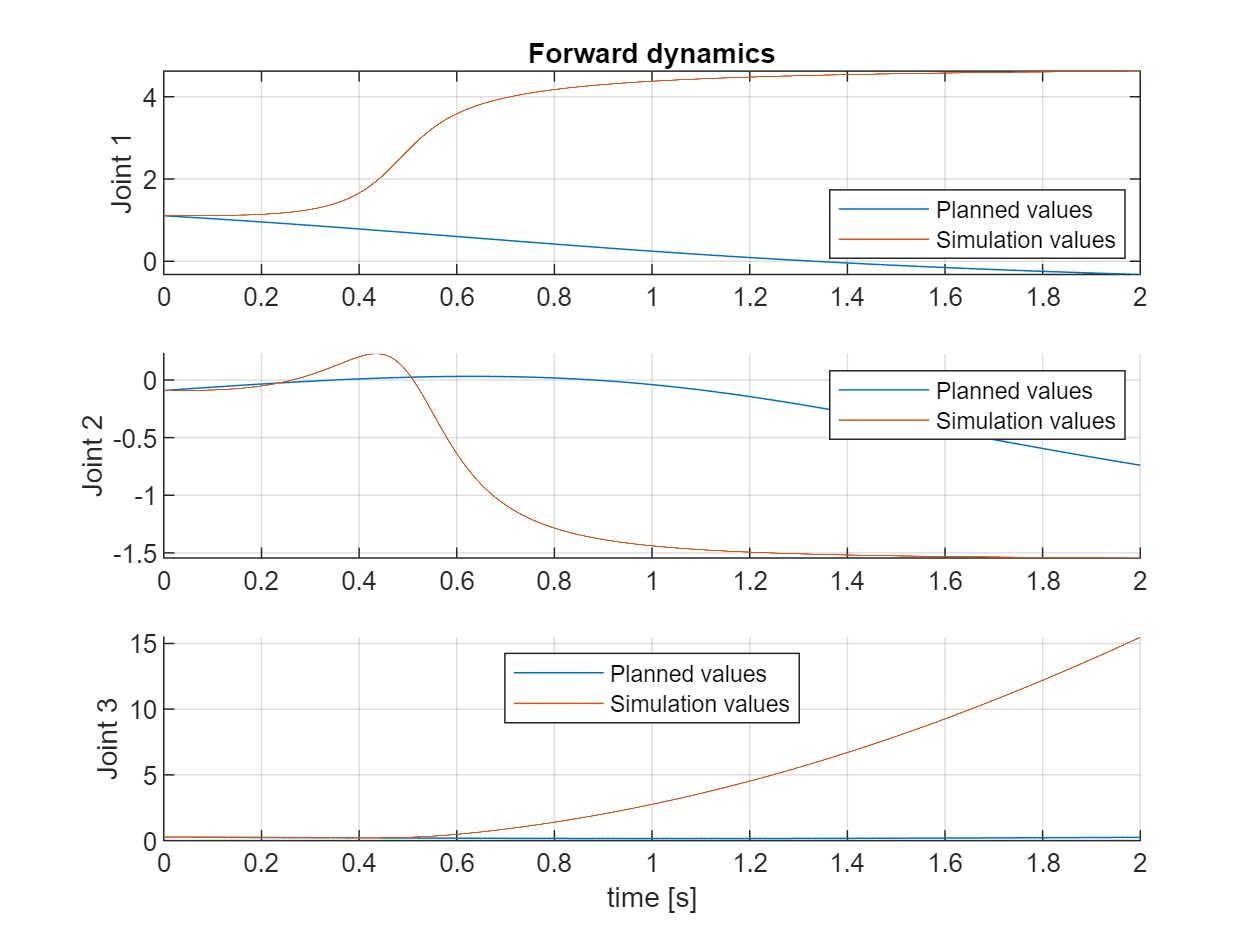

figure('Name','q4')
subplot(3,1,1)
plot(ti,q_(1,:),'DisplayName','Planned values')
hold on 
plot(t_reg,X(:,1),'DisplayName','Simulation values')
grid on
legend("Location","best")
ylabel("Joint 1")
title("Forward dynamics")
hold off

subplot(3,1,2)
hold on 
grid on
plot(ti,q_(2,:),'DisplayName','Planned values')
plot(t_reg,X(:,2),'DisplayName','Simulation values')
legend("Location","best")
ylabel("Joint 2")
hold off

subplot(3,1,3)
hold on 
grid on
plot(ti,q_(3,:),'DisplayName','Planned values')
plot(t_reg,X(:,3),'DisplayName','Simulation values')
legend("Location","best")
xlabel("time [s]")
ylabel("Joint 3")
hold off

x_tau = zeros(200,3);
counter = 1;
for i=1:100:20000
    x_tau(counter,:) = forward_kine(q_reg(i,:));
    counter = counter+1;
end
% x_tau

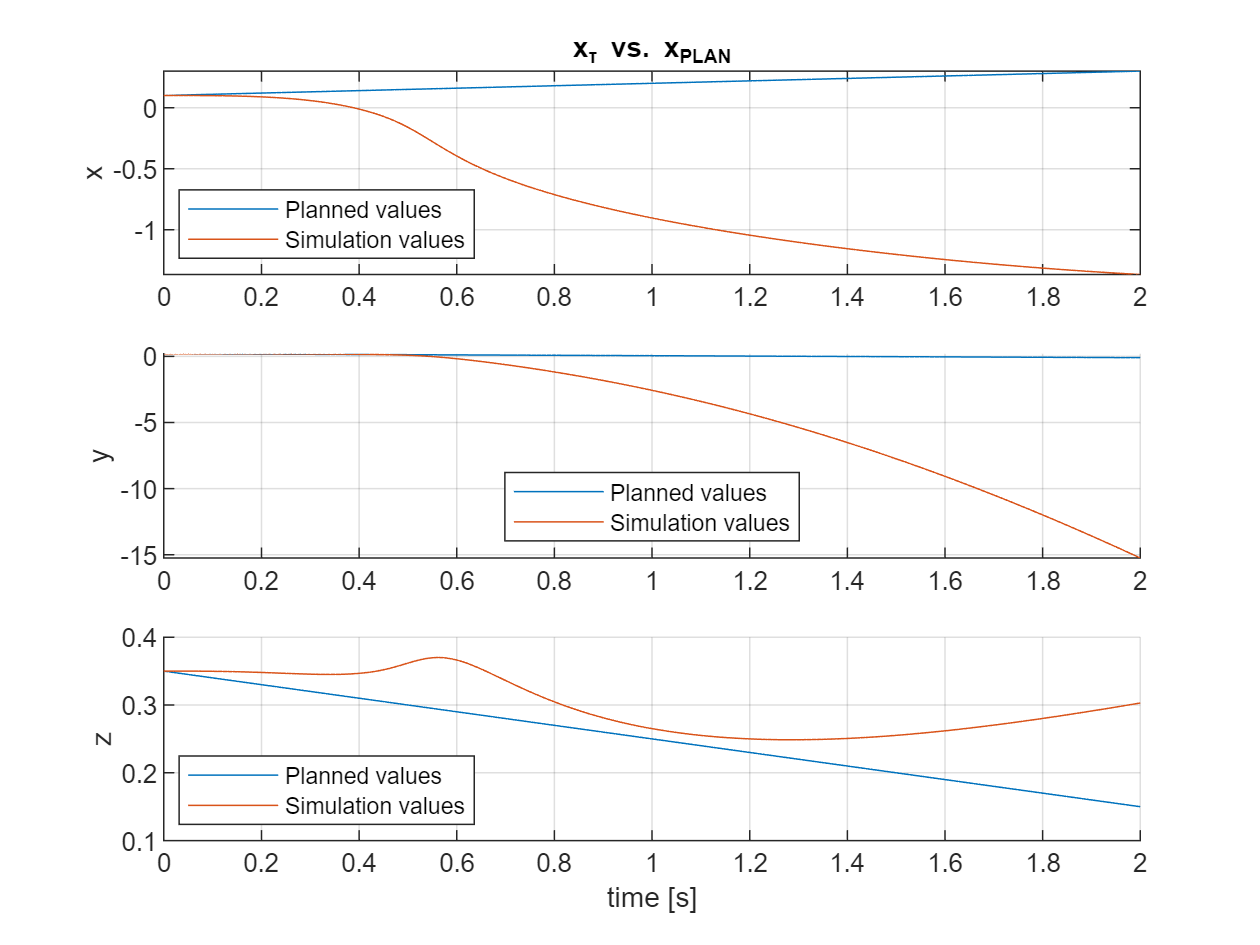

figure('Name','x_tau vs x_plan')
subplot(3,1,1)
plot(ti,x(1,:),'DisplayName','Planned values')
hold on 
plot(ti,x_tau(:,1),'DisplayName','Simulation values')
grid on
legend("Location","best")
ylabel("x")
title("x_{\tau} vs. x_{PLAN}")
hold off

subplot(3,1,2)
hold on 
grid on
plot(ti,x(2,:),'DisplayName','Planned values')
plot(ti,x_tau(:,2),'DisplayName','Simulation values')
legend("Location","best")
ylabel("y")
hold off

subplot(3,1,3)
hold on 
grid on
plot(ti,x(3,:),'DisplayName','Planned values')
plot(ti,x_tau(:,3),'DisplayName','Simulation values')
legend("Location","best")
xlabel("time [s]")
ylabel("z")
hold off

norm = (x'-x_tau)

norm = 200×3
    0.0000    0.0000   -0.0000
    0.0010   -0.0015   -0.0010
    0.0020   -0.0030   -0.0020
    0.0030   -0.0045   -0.0030
    0.0041   -0.0060   -0.0040
    0.0052   -0.0074   -0.0050
    0.0063   -0.0089   -0.0060
    0.0074   -0.0102   -0.0069
    0.0087   -0.0116   -0.0079
    0.0100   -0.0129   -0.0088


error_norm=zeros(1,200);
path_diff = x_init-x_fin;
path_length = sqrt(path_diff(1)^2+path_diff(2)^2+path_diff(3)^2)

path_length = 0.4123


for i=1:200
    error_norm(i)=100*(sqrt(norm(i,1)^2+norm(i,2)^2+norm(i,3)^2)/path_length) ;
end
error_norm

error_norm = 1×200
    0.0000    0.5023    1.0039    1.5049    2.0051    2.5046    3.0035    3.5021    4.0008    4.5003    5.0015    5.5056    6.0139    6.5282    7.0506    7.5835    8.1298    8.6925    9.2751    9.8817   10.5166   11.1847   11.8919   12.6427   13.4418   14.2949   15.2082   16.1886   17.2433   18.3794


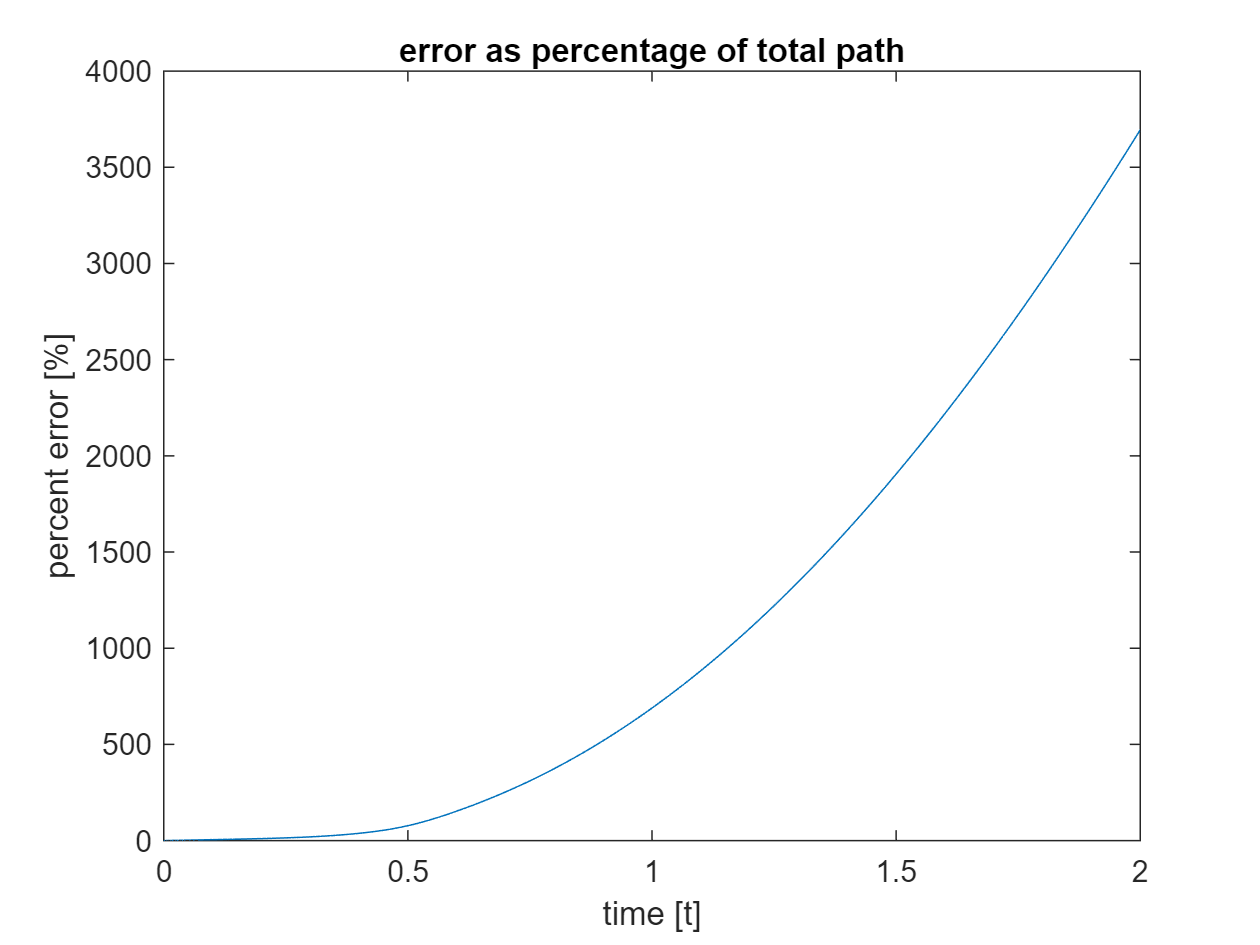

figure
plot(ti,error_norm)
ylabel('percent error [%]')
xlabel('time [t]')
title('error as percentage of total path')

## **Q5**

T = 2;
n = 200;
x_init2 = [0.1, 0.2, 0.36]';
x_fin2 = [0.3, -0.1, 0.15]';
x_shift = x_plan(PROFILE, T, n, x_init2, x_fin2);
v_shift = v_plan(PROFILE, T, n, x_init2, x_fin2);
q_shift = q_plan(x_shift, [1,1], params);
% q_dot_shift = q_dot_plan(q_shift, v, T, 'analytical', params);

% syms q1 q2 q3 qdot1 qdot2 qdot3
% qs = [q1 q2 q3];
% qdots = [qdot1 qdot2 qdot3];
% X = [qs qdots]
tspan=0:0.0001:2;
X_init = [q_shift(:,1)',0, 0, 0] %X_init = [q_shift(:,1)',q_dot_shift(:,1)']

X_init = 1×6
    1.1071   -0.0876    0.2786         0         0         0


[t_reg2,X2] = ode45(@state_eq, tspan, X_init);

index = 1

counter = 201

X_dot = 6×1
         0
         0
         0
   -0.1352
    1.0974
   -0.1849


index = 1

counter = 202

X_dot = 6×1
   -0.0000
    0.0000
   -0.0000
   -0.1352
    1.0974
   -0.1849


index = 1

counter = 203

X_dot = 6×1
   -0.0000
    0.0000
   -0.0000
   -0.1352
    1.0974
   -0.1849


index = 1

counter = 204

X_dot = 6×1
   -0.0000
    0.0001
   -0.0000
   -0.1352
    1.0974
   -0.1849


index = 1

counter = 205

X_dot = 6×1
   -0.0000
    0.0001
   -0.0000
   -0.1352
    1.0974
   -0.1849


index = 1

counter = 206

X_dot = 6×1
   -0.0000
    0.0001
   -0.0000
   -0.1352
    1.0974
   -0.1849


index = 1

counter = 207

X_dot = 6×1
   -0.0000
    0.0001
   -0.0000
   -0.1352
    1.0974
   -0.1849


index = 1

counter = 208

X_dot = 6×1
   -0.0000
    0.0002
   -0.0000
   -0.1352
    1.0974
   -0.1849


index = 1

counter = 209

X_dot = 6×1
   -0.0000
    0.0003
   -0.0000
   -0.1352
    1.0974
   -0.1849


index = 1

counter = 210

X_dot = 6×1
   -0.0001
    0.0005
   -0.0001
   -0.1352
    1.0974
   -0.1849


index = 1

counter = 211

X_dot = 6×1
   -0.0001
    0.0006
   -0.0001
   -0.1352
    1.0974
   -0.1849


index = 1

counter = 212

X_dot = 6×1
   -0.0001
    0.0007
   -0.0001
   -0.1352
    1.0974
   -0.1849


index = 1

counter = 213

X_dot = 6×1
   -0.0001
    0.0007
   -0.0001
   -0.1352
    1.0974
   -0.1849


index = 2

counter = 214

X_dot = 6×1
   -0.0001
    0.0012
   -0.0002
   -0.1092
    1.1255
   -0.1936


index = 2

counter = 215

X_dot = 6×1
   -0.0002
    0.0015
   -0.0003
   -0.1092
    1.1255
   -0.1936


index = 3

counter = 216

X_dot = 6×1
   -0.0004
    0.0028
   -0.0005
   -0.0874
    1.1538
   -0.2020


index = 3

counter = 217

X_dot = 6×1
   -0.0005
    0.0029
   -0.0005
   -0.0874
    1.1538
   -0.2020


index = 4

counter = 218

X_dot = 6×1
   -0.0005
    0.0033
   -0.0005
   -0.0645
    1.1815
   -0.2104


index = 4

counter = 219

X_dot = 6×1
   -0.0003
    0.0035
   -0.0006
   -0.0645
    1.1815
   -0.2104


index = 1

counter = 220

X_dot = 6×1
   -0.0001
    0.0011
   -0.0002
   -0.1352
    1.0974
   -0.1849


index = 2

counter = 221

X_dot = 6×1
   -0.0002
    0.0013
   -0.0002
   -0.1092
    1.1255
   -0.1936


index = 3

counter = 222

X_dot = 6×1
   -0.0001
    0.0026
   -0.0005
   -0.0875
    1.1539
   -0.2020


index = 3

counter = 223

X_dot = 6×1
    0.0002
    0.0031
   -0.0006
   -0.0875
    1.1539
   -0.2020


index = 3

counter = 224

X_dot = 6×1
    0.0001
    0.0033
   -0.0006
   -0.0875
    1.1538
   -0.2020


index = 3

counter = 225

X_dot = 6×1
   -0.0003
    0.0029
   -0.0005
   -0.0874
    1.1538
   -0.2020


index = 3

counter = 226

X_dot = 6×1
   -0.0003
    0.0034
   -0.0006
   -0.0874
    1.1538
   -0.2020


index = 4

counter = 227

X_dot = 6×1
   -0.0003
    0.0036
   -0.0006
   -0.0645
    1.1815
   -0.2104


index = 5

counter = 228

X_dot = 6×1
   -0.0003
    0.0049
   -0.0009
   -0.0399
    1.2095
   -0.2188


index = 5

counter = 229

X_dot = 6×1
   -0.0000
    0.0054
   -0.0010
   -0.0399
    1.2095
   -0.2188


index = 5

counter = 230

X_dot = 6×1
   -0.0001
    0.0057
   -0.0010
   -0.0399
    1.2095
   -0.2188


index = 5

counter = 231

X_dot = 6×1
   -0.0004
    0.0053
   -0.0009
   -0.0399
    1.2095
   -0.2188


index = 6

counter = 232

X_dot = 6×1
   -0.0004
    0.0059
   -0.0010
   -0.0138
    1.2375
   -0.2274


index = 6

counter = 233

X_dot = 6×1
   -0.0004
    0.0062
   -0.0011
   -0.0138
    1.2375
   -0.2273


index = 7

counter = 234

X_dot = 6×1
   -0.0005
    0.0077
   -0.0014
    0.0081
    1.2658
   -0.2357


index = 7

counter = 235

X_dot = 6×1
   -0.0006
    0.0078
   -0.0014
    0.0081
    1.2658
   -0.2356


index = 8

counter = 236

X_dot = 6×1
   -0.0006
    0.0082
   -0.0014
    0.0328
    1.2934
   -0.2440


index = 8

counter = 237

X_dot = 6×1
   -0.0004
    0.0085
   -0.0015
    0.0327
    1.2934
   -0.2440


index = 5

counter = 238

X_dot = 6×1
   -0.0004
    0.0057
   -0.0010
   -0.0398
    1.2095
   -0.2187


index = 6

counter = 239

X_dot = 6×1
   -0.0004
    0.0060
   -0.0011
   -0.0138
    1.2375
   -0.2273


index = 7

counter = 240

X_dot = 6×1
   -0.0003
    0.0074
   -0.0013
    0.0080
    1.2658
   -0.2357


index = 7

counter = 241

X_dot = 6×1
    0.0000
    0.0079
   -0.0015
    0.0080
    1.2658
   -0.2357


index = 7

counter = 242

X_dot = 6×1
   -0.0000
    0.0082
   -0.0015
    0.0081
    1.2658
   -0.2357


index = 7

counter = 243

X_dot = 6×1
   -0.0004
    0.0078
   -0.0014
    0.0081
    1.2658
   -0.2357


index = 7

counter = 244

X_dot = 6×1
   -0.0004
    0.0083
   -0.0015
    0.0081
    1.2658
   -0.2356


index = 8

counter = 245

X_dot = 6×1
   -0.0004
    0.0085
   -0.0015
    0.0328
    1.2934
   -0.2440


index = 9

counter = 246

X_dot = 6×1
   -0.0002
    0.0100
   -0.0018
    0.0558
    1.3214
   -0.2524


index = 9

counter = 247

X_dot = 6×1
    0.0001
    0.0105
   -0.0020
    0.0558
    1.3214
   -0.2524


index = 9

counter = 248

X_dot = 6×1
    0.0000
    0.0108
   -0.0020
    0.0559
    1.3214
   -0.2524


index = 9

counter = 249

X_dot = 6×1
   -0.0003
    0.0103
   -0.0019
    0.0559
    1.3214
   -0.2524


index = 10

counter = 250

X_dot = 6×1
   -0.0003
    0.0110
   -0.0020
    0.0795
    1.3489
   -0.2607


index = 10

counter = 251

X_dot = 6×1
   -0.0003
    0.0114
   -0.0021
    0.0795
    1.3489
   -0.2607


index = 11

counter = 252

X_dot = 6×1
   -0.0002
    0.0131
   -0.0024
    0.1040
    1.3776
   -0.2691


index = 11

counter = 253

X_dot = 6×1
   -0.0003
    0.0133
   -0.0024
    0.1041
    1.3775
   -0.2691


index = 12

counter = 254

X_dot = 6×1
   -0.0003
    0.0137
   -0.0025
    0.1288
    1.4051
   -0.2775


index = 12

counter = 255

X_dot = 6×1
   -0.0001
    0.0140
   -0.0026
    0.1288
    1.4051
   -0.2775


index = 9

counter = 256

X_dot = 6×1
   -0.0003
    0.0109
   -0.0020
    0.0559
    1.3213
   -0.2523


index = 10

counter = 257

X_dot = 6×1
   -0.0003
    0.0112
   -0.0020
    0.0795
    1.3489
   -0.2607


index = 11

counter = 258

X_dot = 6×1
   -0.0001
    0.0127
   -0.0023
    0.1039
    1.3776
   -0.2692


index = 11

counter = 259

X_dot = 6×1
    0.0002
    0.0133
   -0.0025
    0.1040
    1.3776
   -0.2692


index = 11

counter = 260

X_dot = 6×1
    0.0002
    0.0135
   -0.0025
    0.1040
    1.3776
   -0.2692


index = 11

counter = 261

X_dot = 6×1
   -0.0001
    0.0131
   -0.0024
    0.1040
    1.3776
   -0.2692


index = 11

counter = 262

X_dot = 6×1
   -0.0001
    0.0137
   -0.0025
    0.1041
    1.3775
   -0.2691


index = 12

counter = 263

X_dot = 6×1
   -0.0001
    0.0140
   -0.0026
    0.1288
    1.4051
   -0.2775


index = 13

counter = 264

X_dot = 6×1
    0.0002
    0.0156
   -0.0029
    0.1537
    1.4331
   -0.2858


index = 13

counter = 265

X_dot = 6×1
    0.0005
    0.0161
   -0.0031
    0.1537
    1.4331
   -0.2857


index = 13

counter = 266

X_dot = 6×1
    0.0005
    0.0164
   -0.0031
    0.1538
    1.4330
   -0.2857


index = 13

counter = 267

X_dot = 6×1
    0.0001
    0.0160
   -0.0030
    0.1538
    1.4330
   -0.2857


index = 14

counter = 268

X_dot = 6×1
    0.0002
    0.0168
   -0.0031
    0.1775
    1.4606
   -0.2940


index = 14

counter = 269

X_dot = 6×1
    0.0003
    0.0172
   -0.0032
    0.1776
    1.4605
   -0.2940


index = 15

counter = 270

X_dot = 6×1
    0.0005
    0.0190
   -0.0036
    0.2006
    1.4887
   -0.3021


index = 15

counter = 271

X_dot = 6×1
    0.0004
    0.0192
   -0.0036
    0.2007
    1.4887
   -0.3021


index = 16

counter = 272

X_dot = 6×1
    0.0004
    0.0197
   -0.0037
    0.2254
    1.5162
   -0.3104


index = 16

counter = 273

X_dot = 6×1
    0.0006
    0.0199
   -0.0038
    0.2254
    1.5163
   -0.3104


index = 14

counter = 274

X_dot = 6×1
    0.0002
    0.0166
   -0.0031
    0.1775
    1.4606
   -0.2940


index = 14

counter = 275

X_dot = 6×1
    0.0002
    0.0169
   -0.0032
    0.1775
    1.4606
   -0.2940


index = 15

counter = 276

X_dot = 6×1
    0.0004
    0.0183
   -0.0034
    0.2004
    1.4888
   -0.3022


index = 15

counter = 277

X_dot = 6×1
    0.0003
    0.0185
   -0.0035
    0.2005
    1.4888
   -0.3022


index = 15

counter = 278

X_dot = 6×1
    0.0004
    0.0188
   -0.0035
    0.2005
    1.4887
   -0.3022


index = 15

counter = 279

X_dot = 6×1
    0.0005
    0.0190
   -0.0036
    0.2005
    1.4887
   -0.3022


index = 16

counter = 280

X_dot = 6×1
    0.0006
    0.0196
   -0.0037
    0.2253
    1.5163
   -0.3105


index = 16

counter = 281

X_dot = 6×1
    0.0007
    0.0199
   -0.0038
    0.2254
    1.5163
   -0.3104


index = 17

counter = 282

X_dot = 6×1
    0.0008
    0.0214
   -0.0041
    0.2480
    1.5441
   -0.3187


index = 17

counter = 283

X_dot = 6×1
    0.0008
    0.0216
   -0.0041
    0.2481
    1.5441
   -0.3186


index = 17

counter = 284

X_dot = 6×1
    0.0008
    0.0220
   -0.0042
    0.2482
    1.5441
   -0.3186


index = 17

counter = 285

X_dot = 6×1
    0.0010
    0.0221
   -0.0042
    0.2482
    1.5441
   -0.3186


index = 18

counter = 286

X_dot = 6×1
    0.0011
    0.0230
   -0.0044
    0.2745
    1.5722
   -0.3270


index = 18

counter = 287

X_dot = 6×1
    0.0012
    0.0234
   -0.0045
    0.2746
    1.5721
   -0.3269


index = 19

counter = 288

X_dot = 6×1
    0.0015
    0.0255
   -0.0049
    0.2996
    1.5996
   -0.3348


index = 20

counter = 289

X_dot = 6×1
    0.0014
    0.0257
   -0.0050
    0.3226
    1.6272
   -0.3432


index = 20

counter = 290

X_dot = 6×1
    0.0015
    0.0262
   -0.0051
    0.3228
    1.6271
   -0.3431


index = 20

counter = 291

X_dot = 6×1
    0.0018
    0.0265
   -0.0051
    0.3228
    1.6272
   -0.3431


index = 18

counter = 292

X_dot = 6×1
    0.0011
    0.0228
   -0.0044
    0.2744
    1.5722
   -0.3270


index = 18

counter = 293

X_dot = 6×1
    0.0012
    0.0231
   -0.0044
    0.2745
    1.5722
   -0.3269


index = 19

counter = 294

X_dot = 6×1
    0.0014
    0.0248
   -0.0048
    0.2993
    1.5998
   -0.3350


index = 19

counter = 295

X_dot = 6×1
    0.0013
    0.0249
   -0.0048
    0.2994
    1.5997
   -0.3349


index = 19

counter = 296

X_dot = 6×1
    0.0014
    0.0253
   -0.0049
    0.2995
    1.5996
   -0.3349


index = 19

counter = 297

X_dot = 6×1
    0.0016
    0.0255
   -0.0049
    0.2995
    1.5997
   -0.3349


index = 20

counter = 298

X_dot = 6×1
    0.0017
    0.0262
   -0.0051
    0.3227
    1.6272
   -0.3431


index = 20

counter = 299

X_dot = 6×1
    0.0018
    0.0265
   -0.0052
    0.3228
    1.6271
   -0.3431


index = 21

counter = 300

X_dot = 6×1
    0.0021
    0.0282
   -0.0055
    0.3457
    1.6550
   -0.3512


index = 21

counter = 301

X_dot = 6×1
    0.0021
    0.0284
   -0.0055
    0.3458
    1.6549
   -0.3512


index = 21

counter = 302

X_dot = 6×1
    0.0022
    0.0288
   -0.0056
    0.3460
    1.6549
   -0.3511


index = 21

counter = 303

X_dot = 6×1
    0.0023
    0.0290
   -0.0057
    0.3460
    1.6549
   -0.3511


index = 22

counter = 304

X_dot = 6×1
    0.0025
    0.0301
   -0.0059
    0.3706
    1.6827
   -0.3593


index = 22

counter = 305

X_dot = 6×1
    0.0027
    0.0307
   -0.0060
    0.3709
    1.6826
   -0.3591


index = 24

counter = 306

X_dot = 6×1
    0.0032
    0.0334
   -0.0066
    0.4204
    1.7379
   -0.3754


index = 24

counter = 307

X_dot = 6×1
    0.0031
    0.0336
   -0.0066
    0.4206
    1.7377
   -0.3753


index = 25

counter = 308

X_dot = 6×1
    0.0033
    0.0343
   -0.0068
    0.4439
    1.7678
   -0.3841


index = 25

counter = 309

X_dot = 6×1
    0.0036
    0.0347
   -0.0069
    0.4438
    1.7679
   -0.3841


index = 25

counter = 310

X_dot = 6×1
    0.0039
    0.0358
   -0.0071
    0.4444
    1.7677
   -0.3838


index = 26

counter = 311

X_dot = 6×1
    0.0040
    0.0363
   -0.0073
    0.4689
    1.7955
   -0.3921


index = 27

counter = 312

X_dot = 6×1
    0.0050
    0.0394
   -0.0079
    0.4964
    1.8232
   -0.3999


index = 28

counter = 313

X_dot = 6×1
    0.0055
    0.0404
   -0.0082
    0.5189
    1.8504
   -0.4080


index = 28

counter = 314

X_dot = 6×1
    0.0057
    0.0409
   -0.0083
    0.5193
    1.8503
   -0.4079


index = 28

counter = 315

X_dot = 6×1
    0.0051
    0.0403
   -0.0081
    0.5193
    1.8502
   -0.4078


index = 28

counter = 316

X_dot = 6×1
    0.0054
    0.0414
   -0.0084
    0.5199
    1.8500
   -0.4076


index = 29

counter = 317

X_dot = 6×1
    0.0055
    0.0419
   -0.0085
    0.5449
    1.8787
   -0.4160


index = 30

counter = 318

X_dot = 6×1
    0.0066
    0.0449
   -0.0092
    0.5691
    1.9055
   -0.4236


index = 31

counter = 319

X_dot = 6×1
    0.0071
    0.0459
   -0.0094
    0.5955
    1.9336
   -0.4320


index = 31

counter = 320

X_dot = 6×1
    0.0072
    0.0464
   -0.0095
    0.5959
    1.9335
   -0.4318


index = 31

counter = 321

X_dot = 6×1
    0.0067
    0.0458
   -0.0093
    0.5958
    1.9334
   -0.4318


index = 31

counter = 322

X_dot = 6×1
    0.0070
    0.0469
   -0.0096
    0.5966
    1.9332
   -0.4315


index = 32

counter = 323

X_dot = 6×1
    0.0072
    0.0475
   -0.0097
    0.6192
    1.9628
   -0.4402


index = 33

counter = 324

X_dot = 6×1
    0.0083
    0.0505
   -0.0104
    0.6458
    1.9907
   -0.4478


index = 33

counter = 325

X_dot = 6×1
    0.0088
    0.0515
   -0.0107
    0.6462
    1.9906
   -0.4476


index = 34

counter = 326

X_dot = 6×1
    0.0090
    0.0521
   -0.0108
    0.6709
    2.0181
   -0.4557


index = 34

counter = 327

X_dot = 6×1
    0.0085
    0.0515
   -0.0106
    0.6709
    2.0180
   -0.4557


index = 34

counter = 328

X_dot = 6×1
    0.0090
    0.0528
   -0.0109
    0.6719
    2.0177
   -0.4554


index = 35

counter = 329

X_dot = 6×1
    0.0092
    0.0535
   -0.0111
    0.6967
    2.0455
   -0.4636


index = 36

counter = 330

X_dot = 6×1
    0.0106
    0.0572
   -0.0119
    0.7217
    2.0728
   -0.4710


index = 37

counter = 331

X_dot = 6×1
    0.0113
    0.0583
   -0.0122
    0.7469
    2.1008
   -0.4792


index = 37

counter = 332

X_dot = 6×1
    0.0115
    0.0590
   -0.0124
    0.7475
    2.1007
   -0.4790


index = 37

counter = 333

X_dot = 6×1
    0.0109
    0.0583
   -0.0122
    0.7475
    2.1006
   -0.4790


index = 38

counter = 334

X_dot = 6×1
    0.0114
    0.0598
   -0.0125
    0.7730
    2.1300
   -0.4872


index = 38

counter = 335

X_dot = 6×1
    0.0117
    0.0605
   -0.0127
    0.7737
    2.1298
   -0.4870


index = 40

counter = 336

X_dot = 6×1
    0.0130
    0.0642
   -0.0135
    0.8236
    2.1850
   -0.5026


index = 40

counter = 337

X_dot = 6×1
    0.0130
    0.0646
   -0.0136
    0.8242
    2.1849
   -0.5024


index = 41

counter = 338

X_dot = 6×1
    0.0133
    0.0655
   -0.0138
    0.8497
    2.2126
   -0.5106


index = 41

counter = 339

X_dot = 6×1
    0.0137
    0.0659
   -0.0139
    0.8497
    2.2127
   -0.5106


index = 41

counter = 340

X_dot = 6×1
    0.0144
    0.0678
   -0.0143
    0.8515
    2.2123
   -0.5100


index = 42

counter = 341

X_dot = 6×1
    0.0147
    0.0687
   -0.0145
    0.8767
    2.2414
   -0.5181


index = 44

counter = 342

X_dot = 6×1
    0.0169
    0.0738
   -0.0157
    0.9306
    2.2984
   -0.5338


index = 44

counter = 343

X_dot = 6×1
    0.0178
    0.0753
   -0.0161
    0.9316
    2.2984
   -0.5335


index = 45

counter = 344

X_dot = 6×1
    0.0182
    0.0763
   -0.0164
    0.9574
    2.3254
   -0.5414


index = 45

counter = 345

X_dot = 6×1
    0.0175
    0.0754
   -0.0161
    0.9574
    2.3253
   -0.5413


index = 46

counter = 346

X_dot = 6×1
    0.0184
    0.0778
   -0.0167
    0.9824
    2.3548
   -0.5493


index = 46

counter = 347

X_dot = 6×1
    0.0189
    0.0790
   -0.0169
    0.9838
    2.3545
   -0.5488


index = 49

counter = 348

X_dot = 6×1
    0.0213
    0.0848
   -0.0183
    1.0636
    2.4363
   -0.5714


index = 49

counter = 349

X_dot = 6×1
    0.0215
    0.0855
   -0.0184
    1.0649
    2.4360
   -0.5710


index = 50

counter = 350

X_dot = 6×1
    0.0221
    0.0869
   -0.0188
    1.0914
    2.4656
   -0.5792


index = 50

counter = 351

X_dot = 6×1
    0.0226
    0.0876
   -0.0189
    1.0914
    2.4657
   -0.5792


index = 51

counter = 352

X_dot = 6×1
    0.0239
    0.0905
   -0.0196
    1.1180
    2.4936
   -0.5866


index = 52

counter = 353

X_dot = 6×1
    0.0246
    0.0921
   -0.0200
    1.1424
    2.5209
   -0.5942


index = 55

counter = 354

X_dot = 6×1
    0.0284
    0.1000
   -0.0219
    1.2281
    2.6048
   -0.6164


index = 55

counter = 355

X_dot = 6×1
    0.0294
    0.1019
   -0.0224
    1.2302
    2.6047
   -0.6158


index = 56

counter = 356

X_dot = 6×1
    0.0302
    0.1036
   -0.0228
    1.2533
    2.6344
   -0.6240


index = 56

counter = 357

X_dot = 6×1
    0.0297
    0.1030
   -0.0226
    1.2531
    2.6343
   -0.6240


index = 57

counter = 358

X_dot = 6×1
    0.0316
    0.1070
   -0.0235
    1.2846
    2.6608
   -0.6304


index = 58

counter = 359

X_dot = 6×1
    0.0326
    0.1090
   -0.0240
    1.3127
    2.6879
   -0.6378


index = 62

counter = 360

X_dot = 6×1
    0.0381
    0.1197
   -0.0266
    1.4253
    2.8021
   -0.6673


index = 63

counter = 361

X_dot = 6×1
    0.0395
    0.1220
   -0.0272
    1.4535
    2.8292
   -0.6746


index = 63

counter = 362

X_dot = 6×1
    0.0406
    0.1244
   -0.0277
    1.4575
    2.8288
   -0.6735


index = 63

counter = 363

X_dot = 6×1
    0.0400
    0.1237
   -0.0275
    1.4573
    2.8286
   -0.6735


index = 65

counter = 364

X_dot = 6×1
    0.0427
    0.1289
   -0.0288
    1.5133
    2.8846
   -0.6878


index = 66

counter = 365

X_dot = 6×1
    0.0442
    0.1317
   -0.0294
    1.5428
    2.9151
   -0.6955


index = 71

counter = 366

X_dot = 6×1
    0.0517
    0.1457
   -0.0328
    1.6907
    3.0554
   -0.7307


index = 72

counter = 367

X_dot = 6×1
    0.0532
    0.1483
   -0.0334
    1.7206
    3.0821
   -0.7375


index = 73

counter = 368

X_dot = 6×1
    0.0550
    0.1515
   -0.0342
    1.7521
    3.1116
   -0.7446


index = 73

counter = 369

X_dot = 6×1
    0.0549
    0.1513
   -0.0341
    1.7517
    3.1115
   -0.7446


index = 76

counter = 370

X_dot = 6×1
    0.0605
    0.1612
   -0.0365
    1.8457
    3.1969
   -0.7649


index = 78

counter = 371

X_dot = 6×1
    0.0636
    0.1665
   -0.0377
    1.9036
    3.2544
   -0.7791


index = 85

counter = 372

X_dot = 6×1
    0.0802
    0.1939
   -0.0443
    2.1423
    3.4536
   -0.8230


index = 87

counter = 373

X_dot = 6×1
    0.0842
    0.2003
   -0.0459
    2.2048
    3.5111
   -0.8368


index = 89

counter = 374

X_dot = 6×1
    0.0879
    0.2062
   -0.0473
    2.2704
    3.5682
   -0.8500


index = 89

counter = 375

X_dot = 6×1
    0.0866
    0.2043
   -0.0468
    2.2684
    3.5673
   -0.8502


index = 93

counter = 376

X_dot = 6×1
    0.0962
    0.2194
   -0.0504
    2.4060
    3.6832
   -0.8751


index = 95

counter = 377

X_dot = 6×1
    0.1017
    0.2275
   -0.0523
    2.4826
    3.7396
   -0.8865


index = 106

counter = 378

X_dot = 6×1
    0.1303
    0.2685
   -0.0619
    2.8910
    4.0596
   -0.9519


index = 107

counter = 379

X_dot = 6×1
    0.1362
    0.2757
   -0.0636
    2.9453
    4.0900
   -0.9549


index = 110

counter = 380

X_dot = 6×1
    0.1434
    0.2857
   -0.0659
    3.0559
    4.1771
   -0.9732


index = 110

counter = 381

X_dot = 6×1
    0.1428
    0.2863
   -0.0661
    3.0518
    4.1775
   -0.9737


index = 115

counter = 382

X_dot = 6×1
    0.1577
    0.3066
   -0.0709
    3.2535
    4.3250
   -1.0014


index = 117

counter = 383

X_dot = 6×1
    0.1662
    0.3176
   -0.0734
    3.3508
    4.3850
   -1.0100


index = 129

counter = 384

X_dot = 6×1
    0.2098
    0.3722
   -0.0857
    3.9056
    4.7460
   -1.0677


index = 131

counter = 385

X_dot = 6×1
    0.2174
    0.3806
   -0.0874
    4.0139
    4.8076
   -1.0760


index = 134

counter = 386

X_dot = 6×1
    0.2285
    0.3940
   -0.0904
    4.1550
    4.8998
   -1.0906


index = 134

counter = 387

X_dot = 6×1
    0.2299
    0.3966
   -0.0913
    4.1485
    4.9014
   -1.0914


index = 143

counter = 388

X_dot = 6×1
    0.2650
    0.4382
   -0.1005
    4.5979
    5.1796
   -1.1325


index = 147

counter = 389

X_dot = 6×1
    0.2869
    0.4616
   -0.1055
    4.8435
    5.3045
   -1.1448


index = 168

counter = 390

X_dot = 6×1
    0.4042
    0.5795
   -0.1298
    6.2304
    5.9758
   -1.2053


index = 172

counter = 391

X_dot = 6×1
    0.4290
    0.5991
   -0.1330
    6.5513
    6.1033
   -1.2122


index = 177

counter = 392

X_dot = 6×1
    0.4599
    0.6284
   -0.1389
    6.9189
    6.2644
   -1.2231


index = 177

counter = 393

X_dot = 6×1
    0.4589
    0.6328
   -0.1408
    6.8683
    6.2671
   -1.2274


index = 193

counter = 394

X_dot = 6×1
    0.5715
    0.7356
   -0.1609
    8.2068
    6.7932
   -1.2484


index = 201

counter = 395

X_dot = 6×1
    0.6525
    0.7966
   -0.1713
    9.1106
    7.0515
   -1.2360


index = 242

counter = 396

X_dot = 6×1
    1.1533
    1.1114
   -0.2174
   15.0777
    8.2318
   -1.0803


index = 249

counter = 397

X_dot = 6×1
    1.2970
    1.1742
   -0.2207
   16.9091
    8.3330
   -0.9881


index = 259

counter = 398

X_dot = 6×1
    1.4409
    1.2538
   -0.2312
   18.7969
    8.5092
   -0.9113


index = 259

counter = 399

X_dot = 6×1
    1.4053
    1.2497
   -0.2368
   18.1858
    8.5662
   -0.9585


index = 279

counter = 400

X_dot = 6×1
    1.7699
    1.4215
   -0.2560
   22.9565
    8.7064
   -0.7201


index = 289

counter = 401

X_dot = 6×1
    2.0598
    1.5105
   -0.2602
   26.5323
    8.3972
   -0.4914


index = 339

counter = 402

X_dot = 6×1
    4.0531
    1.8240
   -0.2364
   52.9911
    1.7158
    1.5013


index = 348

counter = 403

X_dot = 6×1
    4.6842
    1.8833
   -0.2110
   62.8641
   -1.9428
    2.3224


index = 359

counter = 404

X_dot = 6×1
    5.2818
    1.9033
   -0.1942
   71.5491
   -5.9095
    3.1126


index = 359

counter = 405

X_dot = 6×1
    5.1323
    1.8033
   -0.2039
   66.4649
   -4.8403
    2.7975


index = 376

counter = 406

X_dot = 6×1
    6.2612
    1.7211
   -0.1564
   80.7325
  -13.4969
    4.3262


index = 384

counter = 407

X_dot = 6×1
    7.0983
    1.5146
   -0.1034
   88.1185
  -21.0509
    5.4726


index = 427

counter = 408

X_dot = 6×1
   11.6628
   -0.6758
    0.3093
   83.8142
  -75.1724
   13.2523


index = 434

counter = 409

X_dot = 6×1
   13.7346
   -1.8234
    0.4753
   50.5993
 -108.5108
   18.8844


index = 444

counter = 410

X_dot = 6×1
   14.8993
   -2.2153
    0.5340
   37.1044
 -128.8550
   22.2620


index = 444

counter = 411

X_dot = 6×1
   12.6701
   -1.6558
    0.4899
   64.7659
  -88.8728
   15.5134


index = 366

counter = 412

X_dot = 6×1
    5.6465
    1.7659
   -0.1822
   72.8211
   -8.6134
    3.4770


index = 370

counter = 413

X_dot = 6×1
    5.9589
    1.7143
   -0.1655
   76.1719
  -11.0755
    3.8812


index = 390

counter = 414

X_dot = 6×1
    7.6064
    1.3408
   -0.0664
   91.4530
  -25.9773
    6.1651


index = 393

counter = 415

X_dot = 6×1
    7.9740
    1.1979
   -0.0386
   92.9729
  -29.7726
    6.6882


index = 397

counter = 416

X_dot = 6×1
    8.3914
    1.0741
   -0.0099
   95.6709
  -34.2203
    7.3406


index = 397

counter = 417

X_dot = 6×1
    8.3188
    1.1375
   -0.0175
   96.7216
  -33.3914
    7.2580


index = 405

counter = 418

X_dot = 6×1
    9.0672
    0.8791
    0.0386
  100.5376
  -41.6859
    8.4371


index = 409

counter = 419

X_dot = 6×1
    9.4746
    0.6778
    0.0770
  100.7303
  -46.4329
    9.0855


index = 428

counter = 420

X_dot = 6×1
   11.3124
   -0.4918
    0.2882
   89.5307
  -69.8942
   12.4084


index = 432

counter = 421

X_dot = 6×1
   11.5372
   -0.8350
    0.3396
   81.3115
  -73.2689
   12.9647


index = 436

counter = 422

X_dot = 6×1
   11.9393
   -1.1670
    0.3973
   74.6247
  -78.8296
   13.8725


index = 436

counter = 423

X_dot = 6×1
   12.0293
   -1.0331
    0.3871
   80.0462
  -79.5757
   13.9019


index = 443

counter = 424

X_dot = 6×1
   12.5922
   -1.5927
    0.4848
   66.7506
  -87.5774
   15.2804


index = 447

counter = 425

X_dot = 6×1
   12.7685
   -1.9358
    0.5446
   57.3094
  -90.0448
   15.8421


index = 464

counter = 426

X_dot = 6×1
   13.1837
   -3.5300
    0.8397
    8.9621
  -95.4589
   18.4570


index = 467

counter = 427

X_dot = 6×1
   12.8259
   -3.7113
    0.8831
    4.1499
  -90.2204
   18.1013


index = 471

counter = 428

X_dot = 6×1
   12.7867
   -4.1362
    0.9663
   -8.3152
  -88.7914
   18.6704


index = 471

counter = 429

X_dot = 6×1
   13.3109
   -4.2819
    0.9852
  -14.9574
  -96.0028
   19.8705


index = 479

counter = 430

X_dot = 6×1
   13.1936
   -5.0350
    1.1411
  -38.3704
  -92.4448
   21.1474


index = 483

counter = 431

X_dot = 6×1
   12.9283
   -5.3802
    1.2303
  -47.5234
  -86.8868
   21.3487


index = 503

counter = 432

X_dot = 6×1
   11.7283
   -6.5441
    1.6279
  -76.7522
  -60.9925
   22.6103


index = 506

counter = 433

X_dot = 6×1
   11.5958
   -6.1345
    1.6355
  -69.0569
  -60.7419
   22.1361


index = 510

counter = 434

X_dot = 6×1
   11.1322
   -6.3602
    1.7478
  -72.1094
  -51.3028
   21.9420


index = 510

counter = 435

X_dot = 6×1
   10.9628
   -7.2092
    1.8426
  -87.3008
  -43.2809
   22.9822


index = 518

counter = 436

X_dot = 6×1
   10.2695
   -7.5529
    2.0251
  -90.5354
  -28.1816
   23.0861


index = 522

counter = 437

X_dot = 6×1
    9.8939
   -7.5899
    2.1173
  -89.2424
  -20.5837
   22.7381


index = 542

counter = 438

X_dot = 6×1
    8.3948
   -7.6180
    2.5228
  -83.7045
    7.5455
   21.9966


index = 546

counter = 439

X_dot = 6×1
    8.5718
   -7.4232
    2.5222
  -86.8405
    3.0621
   22.9447


index = 550

counter = 440

X_dot = 6×1
    8.2259
   -7.2921
    2.6140
  -83.0426
    8.1355
   22.4379


index = 550

counter = 441

X_dot = 6×1
    7.5706
   -7.5349
    2.7231
  -75.6641
   21.1642
   20.6366


index = 559

counter = 442

X_dot = 6×1
    6.9223
   -7.3535
    2.8999
  -69.2376
   30.0225
   19.7379


index = 563

counter = 443

X_dot = 6×1
    6.6602
   -7.1775
    2.9796
  -66.1963
   32.4576
   19.2796


index = 584

counter = 444

X_dot = 6×1
    5.3918
   -6.5061
    3.3673
  -52.1485
   42.3451
   17.4160


index = 588

counter = 445

X_dot = 6×1
    5.1882
   -6.6409
    3.4244
  -51.6375
   45.2165
   17.8934


index = 593

counter = 446

X_dot = 6×1
    4.9790
   -6.4308
    3.4972
  -48.7440
   45.1952
   17.5206


index = 593

counter = 447

X_dot = 6×1
    4.9866
   -6.0175
    3.5116
  -46.1252
   41.9635
   16.3109


index = 606

counter = 448

X_dot = 6×1
    4.4014
   -5.4852
    3.7185
  -38.6970
   41.7869
   15.0743


index = 612

counter = 449

X_dot = 6×1
    4.2148
   -5.2215
    3.8043
  -36.3961
   40.1931
   14.8334


index = 644

counter = 450

X_dot = 6×1
    3.0810
   -4.2455
    4.2989
  -23.6105
   36.3856
   12.8870


index = 649

counter = 451

X_dot = 6×1
    2.5687
   -4.5218
    4.4834
  -19.1268
   42.3230
   12.6672


index = 656

counter = 452

X_dot = 6×1
    2.4175
   -4.3401
    4.5581
  -17.4105
   40.3145
   12.5842


index = 656

counter = 453

X_dot = 6×1
    2.9541
   -3.6575
    4.4063
  -21.4228
   29.8670
   12.5372


index = 671

counter = 454

X_dot = 6×1
    2.6460
   -3.2279
    4.5866
  -18.0511
   26.2673
   11.9341


index = 678

counter = 455

X_dot = 6×1
    2.5465
   -3.0713
    4.6670
  -17.0461
   24.6978
   11.9045


index = 714

counter = 456

X_dot = 6×1
    1.9355
   -2.2944
    5.1277
  -11.2538
   18.0317
   10.8596


index = 720

counter = 457

X_dot = 6×1
    1.6520
   -2.1504
    5.2988
   -8.8951
   17.5822
   10.1131


index = 728

counter = 458

X_dot = 6×1
    1.5655
   -2.0309
    5.3833
   -8.1709
   16.3629
   10.0541


index = 728

counter = 459

X_dot = 6×1
    1.8653
   -2.0730
    5.2418
  -10.5489
   15.5319
   10.9942


index = 747

counter = 460

X_dot = 6×1
    1.6688
   -1.7836
    5.4466
   -8.8799
   12.9557
   10.7158


index = 756

counter = 461

X_dot = 6×1
    1.6055
   -1.6929
    5.5432
   -8.3803
   12.0645
   10.7378


index = 803

counter = 462

X_dot = 6×1
    1.2170
   -1.1680
    6.0730
   -5.5054
    7.7070
   10.2311


index = 811

counter = 463

X_dot = 6×1
    1.0368
   -0.9649
    6.2390
   -4.2799
    6.3586
    9.7586


index = 822

counter = 464

X_dot = 6×1
    0.9804
   -0.8904
    6.3439
   -3.9224
    5.7380
    9.7422


index = 822

counter = 465

X_dot = 6×1
    1.1718
   -1.0897
    6.2308
   -5.2006
    6.8882
   10.3932


index = 844

counter = 466

X_dot = 6×1
    1.0532
   -0.9327
    6.4678
   -4.4326
    5.6579
   10.2915


index = 856

counter = 467

X_dot = 6×1
    1.0136
   -0.8857
    6.5837
   -4.1885
    5.2637
   10.3135


index = 913

counter = 468

X_dot = 6×1
    0.7808
   -0.5963
    7.1898
   -2.8442
    3.2031
   10.1296


index = 923

counter = 469

X_dot = 6×1
    0.6847
   -0.4622
    7.3380
   -2.3192
    2.3961
    9.9307


index = 936

counter = 470

X_dot = 6×1
    0.6496
   -0.4218
    7.4656
   -2.1426
    2.1290
    9.9298


index = 936

counter = 471

X_dot = 6×1
    0.7454
   -0.5671
    7.4022
   -2.6636
    2.9443
   10.2152


index = 961

counter = 472

X_dot = 6×1
    0.6768
   -0.4913
    7.6651
   -2.3154
    2.4483
   10.1849


index = 974

counter = 473

X_dot = 6×1
    0.6526
   -0.4678
    7.7956
   -2.1963
    2.2861
   10.1980


index = 1038

counter = 474

X_dot = 6×1
    0.5177
   -0.3269
    8.4602
   -1.5706
    1.4437
   10.1409


index = 1050

counter = 475

X_dot = 6×1
    0.4709
   -0.2660
    8.5966
   -1.3614
    1.1310
   10.0660


index = 1064

counter = 476

X_dot = 6×1
    0.4495
   -0.2459
    8.7412
   -1.2726
    1.0204
   10.0644


index = 1064

counter = 477

X_dot = 6×1
    0.4907
   -0.3092
    8.7128
   -1.4574
    1.3256
   10.1713


index = 1095

counter = 478

X_dot = 6×1
    0.4462
   -0.2688
    9.0232
   -1.2732
    1.1049
   10.1541


index = 1110

counter = 479

X_dot = 6×1
    0.4303
   -0.2561
    9.1778
   -1.2088
    1.0325
   10.1579


index = 1186

counter = 480

X_dot = 6×1
    0.3427
   -0.1807
    9.9568
   -0.8742
    0.6560
   10.0979


index = 1200

counter = 481

X_dot = 6×1
    0.3138
   -0.1485
   10.1058
   -0.7671
    0.5166
   10.0513


index = 1217

counter = 482

X_dot = 6×1
    0.2998
   -0.1377
   10.2766
   -0.7185
    0.4672
   10.0377


index = 1217

counter = 483

X_dot = 6×1
    0.3241
   -0.1709
   10.2597
   -0.8094
    0.6028
   10.0910


index = 1253

counter = 484

X_dot = 6×1
    0.2946
   -0.1490
   10.6279
   -0.7079
    0.5028
   10.0500


index = 1272

counter = 485

X_dot = 6×1
    0.2840
   -0.1421
   10.8103
   -0.6719
    0.4700
   10.0326


index = 1363

counter = 486

X_dot = 6×1
    0.2260
   -0.1010
   11.7226
   -0.4867
    0.2990
    9.8809


index = 1379

counter = 487

X_dot = 6×1
    0.2074
   -0.0834
   11.8895
   -0.4291
    0.2354
    9.8304


index = 1399

counter = 488

X_dot = 6×1
    0.1980
   -0.0775
   12.0888
   -0.4019
    0.2130
    9.7901


index = 1399

counter = 489

X_dot = 6×1
    0.2134
   -0.0956
   12.0791
   -0.4496
    0.2750
    9.8191


index = 1439

counter = 490

X_dot = 6×1
    0.1954
   -0.0846
   12.4719
   -0.3975
    0.2332
    9.7271


index = 1459

counter = 491

X_dot = 6×1
    0.1888
   -0.0810
   12.6641
   -0.3783
    0.2189
    9.6810


index = 1559

counter = 492

X_dot = 6×1
    0.1533
   -0.0604
   13.6207
   -0.2819
    0.1463
    9.3980


index = 1577

counter = 493

X_dot = 6×1
    0.1430
   -0.0526
   13.7914
   -0.2551
    0.1226
    9.3331


index = 1599

counter = 494

X_dot = 6×1
    0.1371
   -0.0495
   13.9981
   -0.2403
    0.1126
    9.2631


index = 1599

counter = 495

X_dot = 6×1
    0.1446
   -0.0569
   13.9925
   -0.2598
    0.1336
    9.2761


index = 1639

counter = 496

X_dot = 6×1
    0.1343
   -0.0515
   14.3635
   -0.2340
    0.1164
    9.1421


index = 1659

counter = 497

X_dot = 6×1
    0.1302
   -0.0496
   14.5430
   -0.2238
    0.1101
    9.0743


index = 1759

counter = 498

X_dot = 6×1
    0.1093
   -0.0394
   15.4332
   -0.1745
    0.0791
    8.7107


index = 1777

counter = 499

X_dot = 6×1
    0.1042
   -0.0363
   15.5888
   -0.1629
    0.0709
    8.6397


index = 1799

counter = 500

X_dot = 6×1
    0.1005
   -0.0347
   15.7799
   -0.1548
    0.0662
    8.5565


index = 1799

counter = 501

X_dot = 6×1
    0.1035
   -0.0371
   15.7781
   -0.1613
    0.0721
    8.5613


index = 1839

counter = 502

X_dot = 6×1
    0.0970
   -0.0342
   16.1228
   -0.1471
    0.0641
    8.4075


index = 1860

counter = 503

X_dot = 6×1
    0.0944
   -0.0331
   16.2881
   -0.1414
    0.0609
    8.3272


index = 1960

counter = 504

X_dot = 6×1
    0.0812
   -0.0274
   17.1046
   -0.1136
    0.0460
    7.9392


index = 1978

counter = 505

X_dot = 6×1
    0.0782
   -0.0259
   17.2423
   -0.1077
    0.0424
    7.8682


index = 2001

counter = 506

X_dot = 6×1
    0.0758
   -0.0250
   17.4179
   -0.1030
    0.0401
    7.7799


index = 2001

counter = 507

X_dot = 6×1
    0.0772
   -0.0259
   17.4229
   -0.1056
    0.0421
    7.7819


counter = 1;

q_reg2=X2(:,1:3);
qdot_re2g=X2(:,4:6);

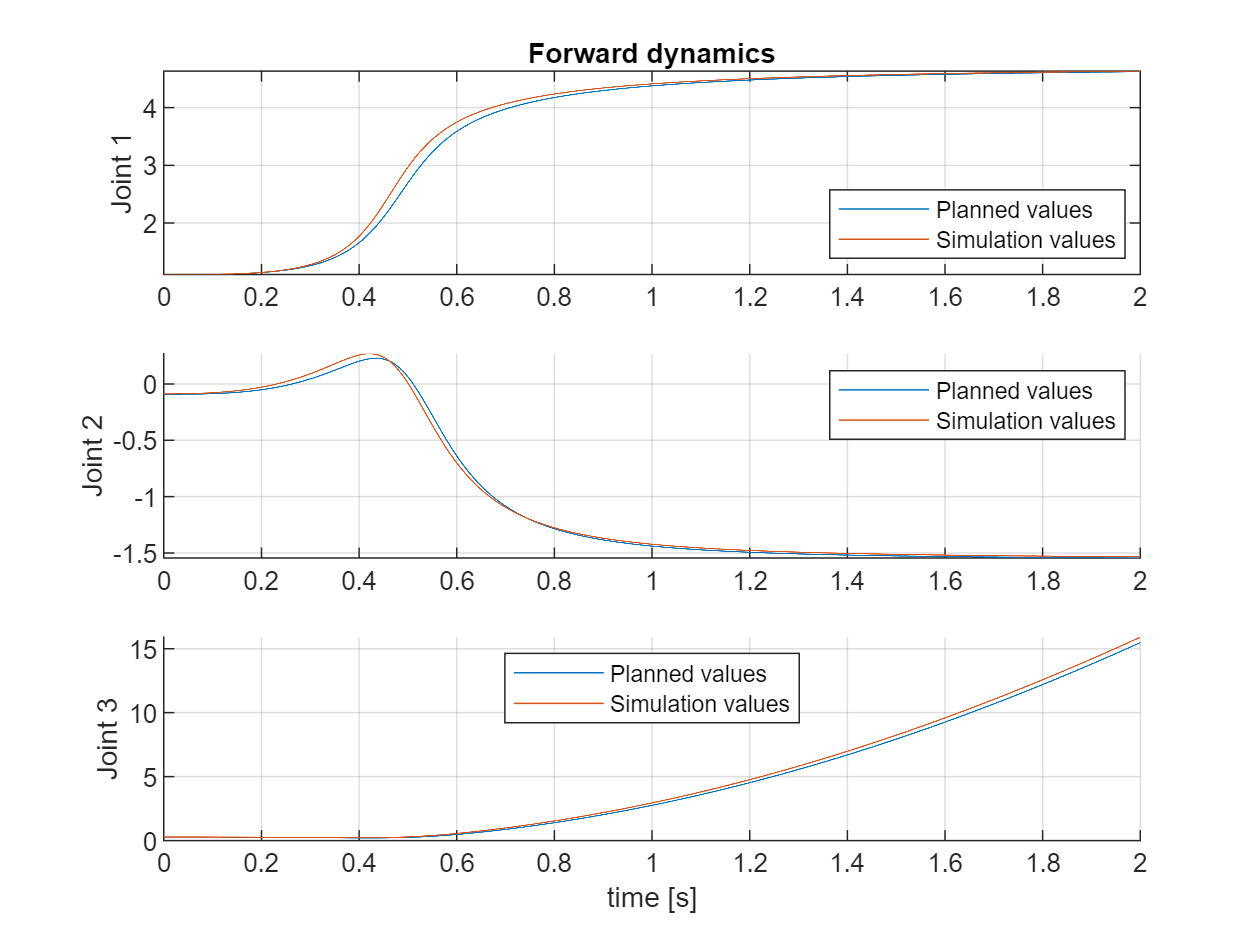

figure('Name','q5')
subplot(3,1,1)
plot(t_reg,X(:,1),'DisplayName','Planned values')
hold on 
plot(t_reg2,X2(:,1),'DisplayName','Simulation values')
grid on
legend("Location","best")
ylabel("Joint 1")
title("Forward dynamics")
hold off

subplot(3,1,2)
hold on
grid on
plot(t_reg,X(:,2),'DisplayName','Planned values')
plot(t_reg2,X2(:,2),'DisplayName','Simulation values')
legend("Location","best")
ylabel("Joint 2")
hold off

subplot(3,1,3)
hold on 
grid on
plot(t_reg,X(:,3),'DisplayName','Planned values')
plot(t_reg2,X2(:,3),'DisplayName','Simulation values')
legend("Location","best")
xlabel("time [s]")
ylabel("Joint 3")
hold off

x_tau_shift = zeros(200,3);
counter = 1;
for i=1:100:20000
    x_tau_shift(counter,:) = forward_kine(q_reg2(i,:));
    counter = counter+1;
end

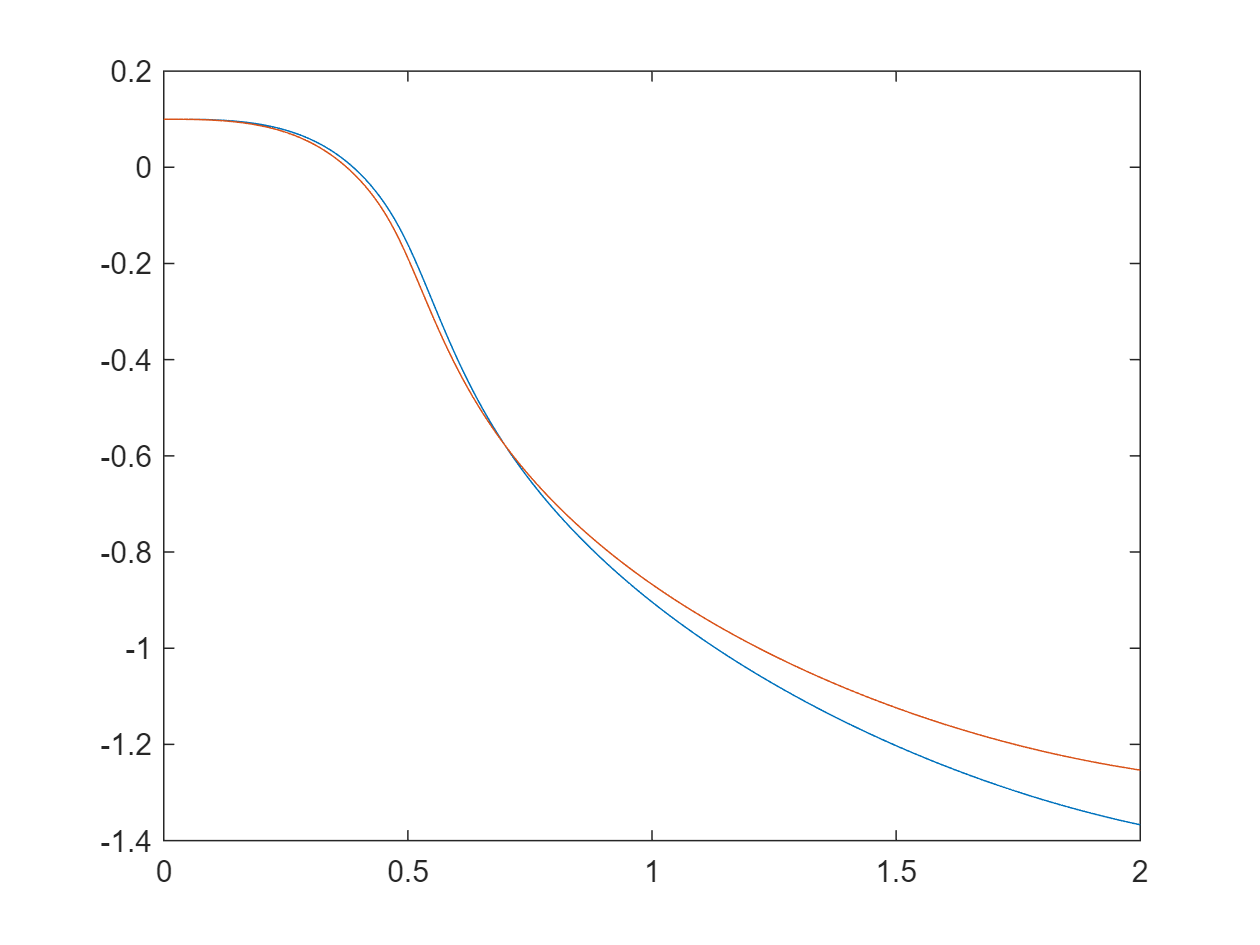

% figure()
% plot(ti, x_tau(:,1))
% hold on;
% plot(ti,x_tau_shift(:,1))
% hold off;

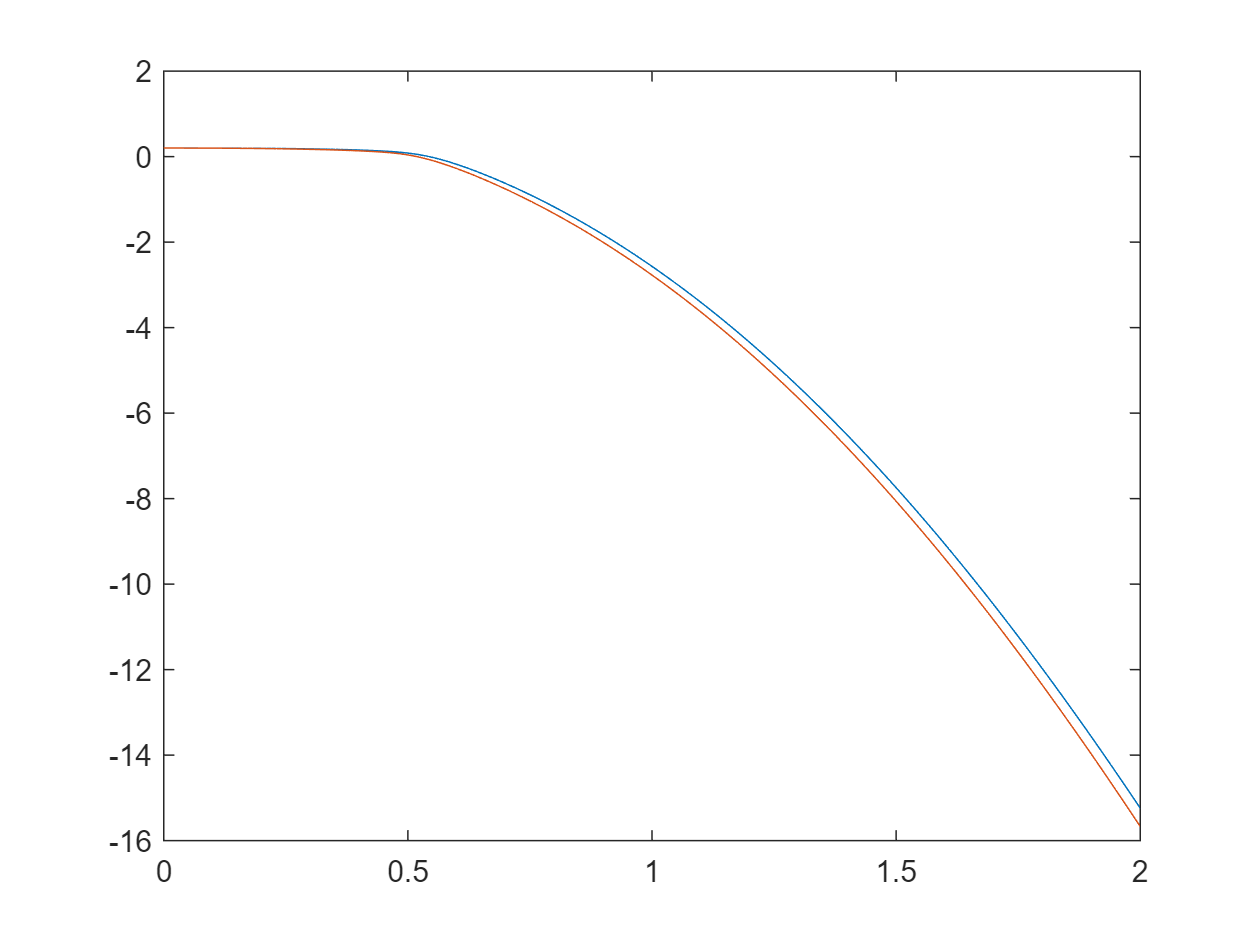

% 
% plot(ti, x_tau(:,2))
% hold on;
% plot(ti,x_tau_shift(:,2))
% hold off;

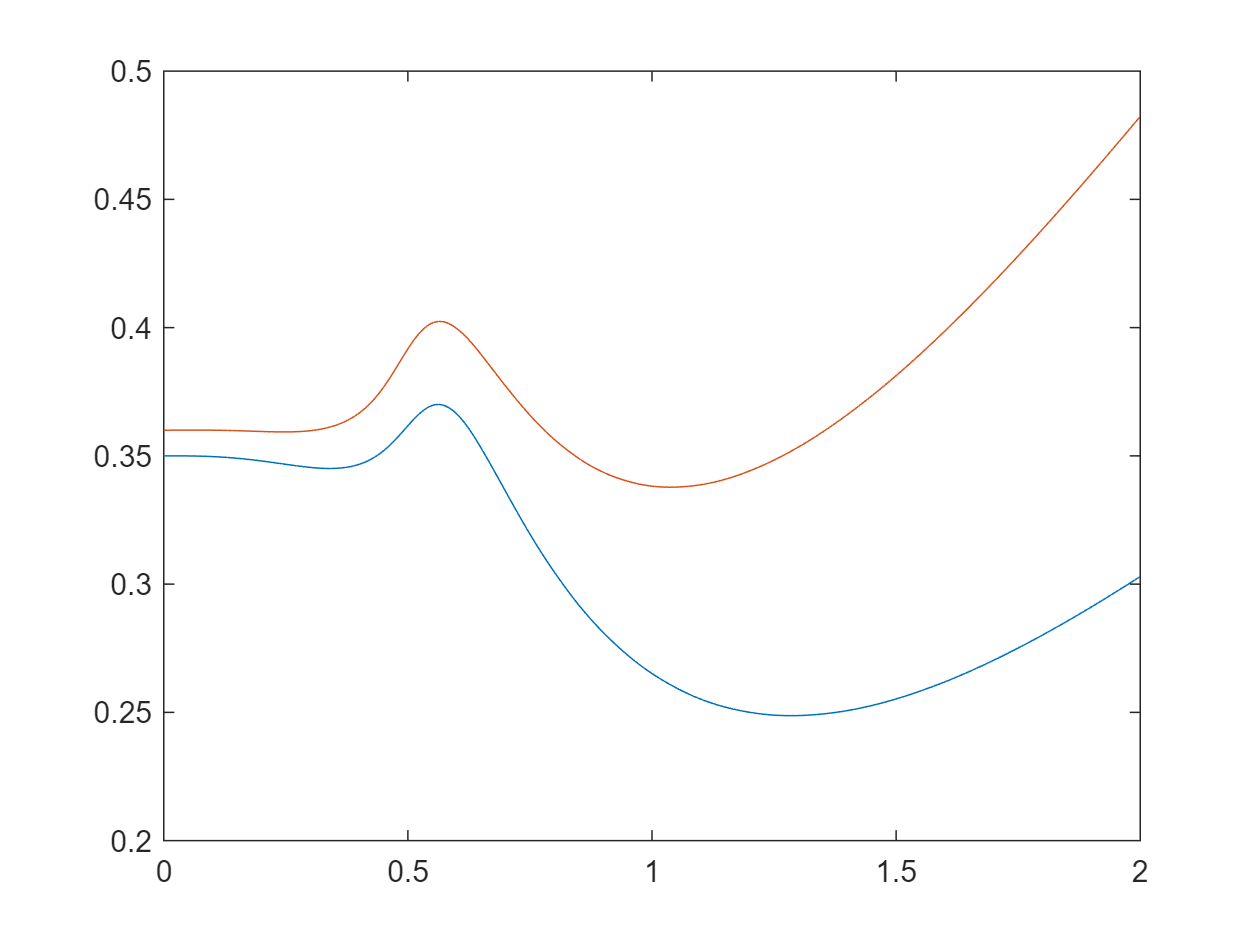

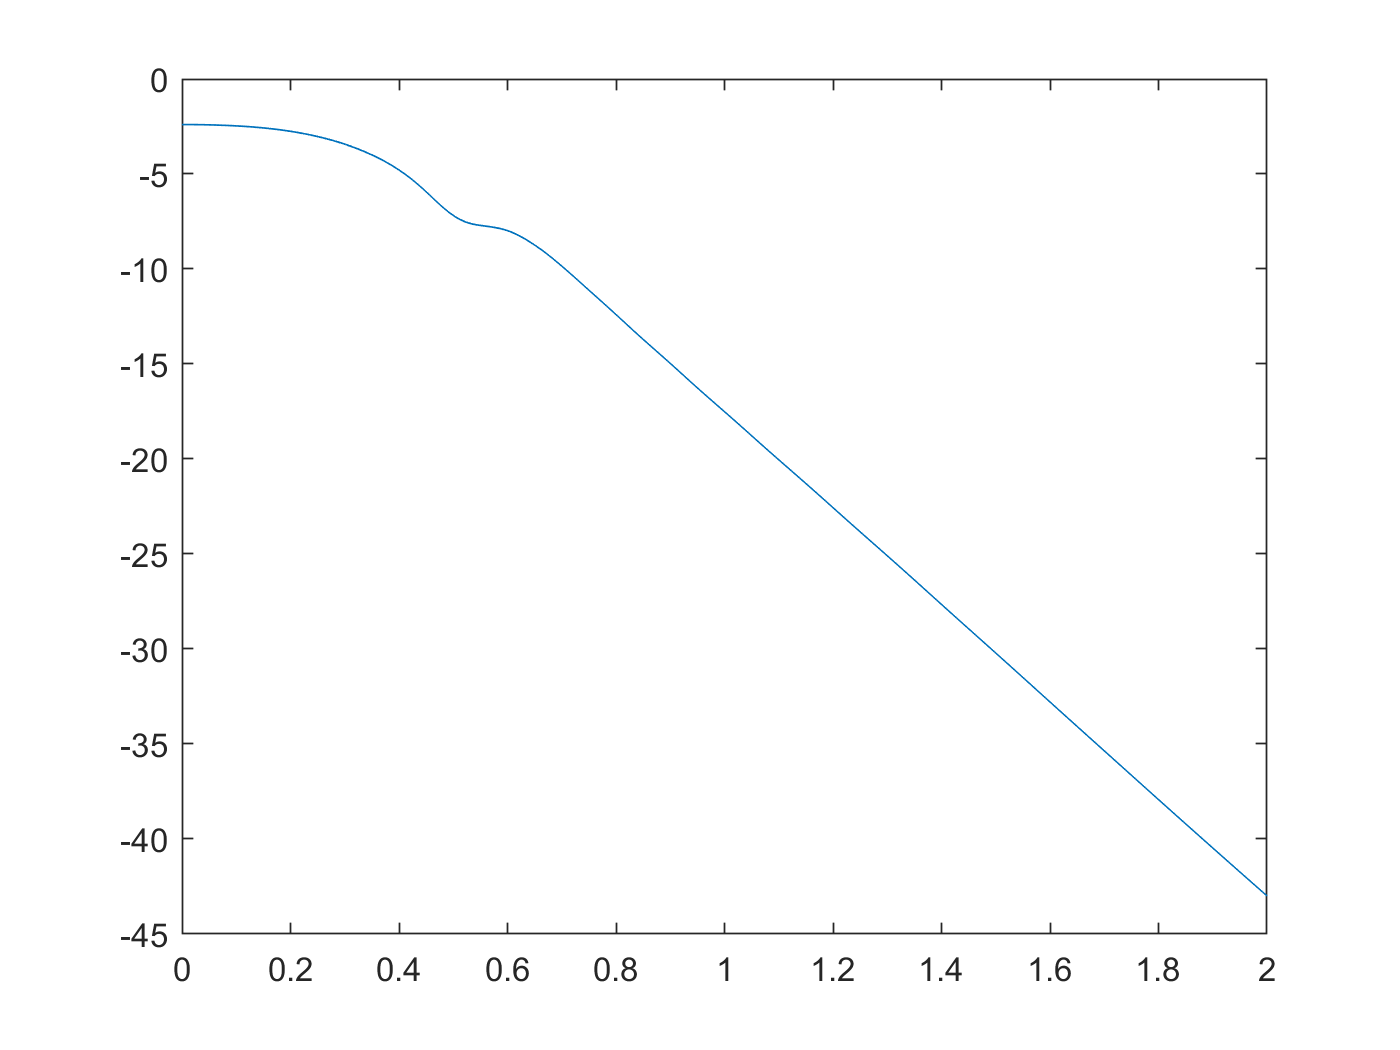

% 
% plot(ti, x_tau(:,3))
% hold on;
% plot(ti,x_tau_shift(:,3))
% hold off;

norm = (x_tau-x_tau_shift)

norm =    -0.0000   -0.0000   -0.0100
    0.0000    0.0000   -0.0100
    0.0000    0.0001   -0.0100
    0.0001    0.0001   -0.0100
    0.0001    0.0002   -0.0100
    0.0002    0.0003   -0.0101
    0.0002    0.0005   -0.0101
    0.0003    0.0007   -0.0101
    0.0004    0.0008   -0.0102
    0.0005    0.0011   -0.0102


error_norm=zeros(1,200);
path_diff = x_init2-x_fin;
path_length = sqrt(path_diff(1)^2+path_diff(2)^2+path_diff(3)^2)

path_length = 0.4173


for i=1:200
    error_norm(i)=100*(sqrt(norm(i,1)^2+norm(i,2)^2+norm(i,3)^2)/path_length) ;
end
error_norm

error_norm =     2.3966    2.3973    2.3993    2.4028    2.4080    2.4151    2.4246    2.4367    2.4519    2.4708    2.4939    2.5216    2.5546    2.5935    2.6386    2.6906    2.7499    2.8171    2.8924    2.9763    3.0691    3.1711    3.2829    3.4046    3.5360    3.6775    3.8296    3.9913    4.1646    4.3515    4.5529    4.7686    4.9980    5.2416    5.4984    5.7697    6.0594    6.3689    6.6991    7.0501    7.4243    7.8254    8.2607    8.7410    9.2814    9.9024   10.6229   11.4627   12.4294   13.5188


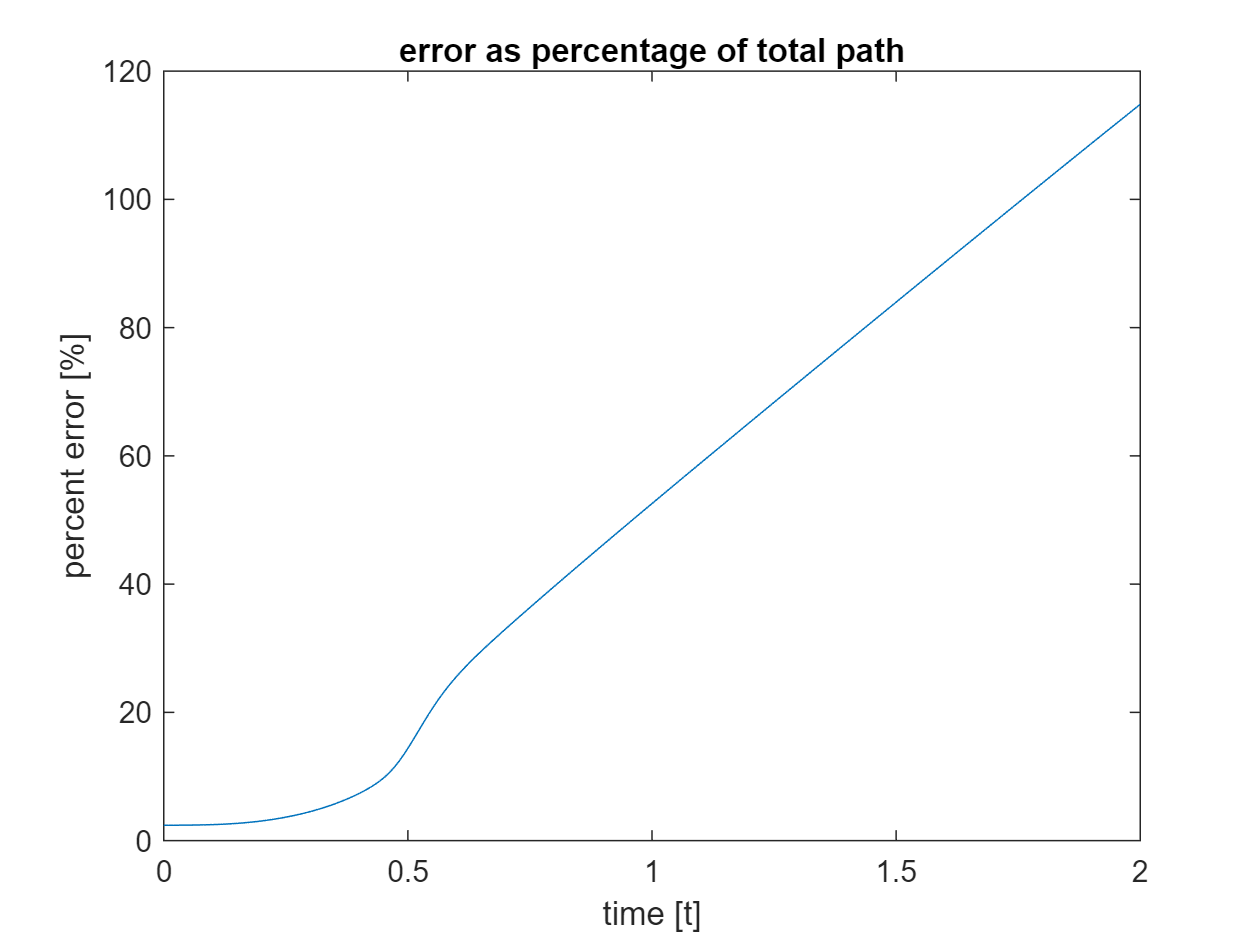

figure
plot(ti,error_norm)
ylabel('percent error [%]')
xlabel('time [t]')
title('error as percentage of total path')

## **Q6**

counter = 1;
% syms q1 q2 q3 qdot1 qdot2 qdot3
% qs = [q1 q2 q3];
% qdots = [qdot1 qdot2 qdot3];
% X = [qs qdots]
tspan=0:0.0001:2;
X0_3 = [q_(:,1)',0, 0, 0] %X0 = [q_(:,1)',q_dot_(:,1)']

X0_3 =     1.1071   -0.0909    0.2693         0         0         0


[t_reg,X3] = ode45(@state_eq_q6, tspan, X0_3);

index = 1

counter = 1

X_dot =          0
         0
         0
   -2.2453
    4.4808
   -0.9817


index = 1

counter = 2

X_dot =    -0.0000
    0.0000
   -0.0000
   -2.2453
    4.4808
   -0.9817


index = 1

counter = 3

X_dot =    -0.0000
    0.0001
   -0.0000
   -2.2453
    4.4808
   -0.9817


index = 1

counter = 4

X_dot =    -0.0001
    0.0002
   -0.0000
   -2.2453
    4.4808
   -0.9817


index = 1

counter = 5

X_dot =    -0.0001
    0.0002
   -0.0000
   -2.2453
    4.4808
   -0.9817


index = 1

counter = 6

X_dot =    -0.0001
    0.0002
   -0.0000
   -2.2453
    4.4808
   -0.9817


index = 1

counter = 7

X_dot =    -0.0001
    0.0002
   -0.0000
   -2.2453
    4.4808
   -0.9817


index = 1

counter = 8

X_dot =    -0.0002
    0.0004
   -0.0001
   -2.2453
    4.4808
   -0.9817


index = 1

counter = 9

X_dot =    -0.0003
    0.0005
   -0.0001
   -2.2453
    4.4808
   -0.9817


index = 1

counter = 10

X_dot =    -0.0005
    0.0010
   -0.0002
   -2.2453
    4.4808
   -0.9817


index = 1

counter = 11

X_dot =    -0.0005
    0.0011
   -0.0002
   -2.2453
    4.4808
   -0.9817


index = 1

counter = 12

X_dot =    -0.0006
    0.0012
   -0.0003
   -2.2453
    4.4808
   -0.9817


index = 1

counter = 13

X_dot =    -0.0006
    0.0012
   -0.0003
   -2.2453
    4.4808
   -0.9817


index = 1

counter = 14

X_dot =    -0.0011
    0.0022
   -0.0005
   -2.2453
    4.4808
   -0.9817


index = 1

counter = 15

X_dot =    -0.0014
    0.0027
   -0.0006
   -2.2453
    4.4808
   -0.9817


index = 2

counter = 16

X_dot =    -0.0026
    0.0052
   -0.0011
   -2.2222
    4.5065
   -0.9894


index = 2

counter = 17

X_dot =    -0.0028
    0.0057
   -0.0012
   -2.2222
    4.5065
   -0.9894


index = 2

counter = 18

X_dot =    -0.0031
    0.0062
   -0.0014
   -2.2222
    4.5064
   -0.9894


index = 2

counter = 19

X_dot =    -0.0031
    0.0062
   -0.0014
   -2.2222
    4.5064
   -0.9894


index = 2

counter = 20

X_dot =    -0.0039
    0.0079
   -0.0017
   -2.2223
    4.5064
   -0.9894


index = 2

counter = 21

X_dot =    -0.0044
    0.0088
   -0.0019
   -2.2223
    4.5064
   -0.9894


index = 3

counter = 22

X_dot =    -0.0064
    0.0130
   -0.0029
   -2.2031
    4.5323
   -0.9969


index = 4

counter = 23

X_dot =    -0.0068
    0.0137
   -0.0030
   -2.1827
    4.5576
   -1.0045


index = 4

counter = 24

X_dot =    -0.0073
    0.0147
   -0.0032
   -2.1828
    4.5575
   -1.0044


index = 4

counter = 25

X_dot =    -0.0073
    0.0147
   -0.0032
   -2.1828
    4.5575
   -1.0044


index = 4

counter = 26

X_dot =    -0.0082
    0.0167
   -0.0037
   -2.1829
    4.5575
   -1.0043


index = 4

counter = 27

X_dot =    -0.0087
    0.0176
   -0.0039
   -2.1829
    4.5574
   -1.0043


index = 5

counter = 28

X_dot =    -0.0110
    0.0225
   -0.0050
   -2.1613
    4.5828
   -1.0117


index = 6

counter = 29

X_dot =    -0.0115
    0.0234
   -0.0051
   -2.1382
    4.6085
   -1.0194


index = 6

counter = 30

X_dot =    -0.0120
    0.0245
   -0.0054
   -2.1383
    4.6084
   -1.0193


index = 6

counter = 31

X_dot =    -0.0119
    0.0245
   -0.0054
   -2.1383
    4.6084
   -1.0193


index = 6

counter = 32

X_dot =    -0.0131
    0.0269
   -0.0059
   -2.1385
    4.6083
   -1.0192


index = 7

counter = 33

X_dot =    -0.0136
    0.0281
   -0.0062
   -2.1192
    4.6342
   -1.0267


index = 8

counter = 34

X_dot =    -0.0162
    0.0343
   -0.0076
   -2.0978
    4.6590
   -1.0338


index = 8

counter = 35

X_dot =    -0.0164
    0.0358
   -0.0079
   -2.0980
    4.6590
   -1.0337


index = 9

counter = 36

X_dot =    -0.0170
    0.0371
   -0.0082
   -2.0777
    4.6846
   -1.0412


index = 9

counter = 37

X_dot =    -0.0174
    0.0366
   -0.0081
   -2.0777
    4.6845
   -1.0412


index = 9

counter = 38

X_dot =    -0.0189
    0.0400
   -0.0088
   -2.0781
    4.6842
   -1.0408


index = 10

counter = 39

X_dot =    -0.0197
    0.0417
   -0.0092
   -2.0573
    4.7093
   -1.0482


index = 11

counter = 40

X_dot =    -0.0232
    0.0506
   -0.0112
   -2.0368
    4.7347
   -1.0549


index = 12

counter = 41

X_dot =    -0.0235
    0.0527
   -0.0117
   -2.0151
    4.7599
   -1.0623


index = 12

counter = 42

X_dot =    -0.0244
    0.0545
   -0.0121
   -2.0154
    4.7596
   -1.0621


index = 12

counter = 43

X_dot =    -0.0249
    0.0538
   -0.0119
   -2.0154
    4.7595
   -1.0620


index = 13

counter = 44

X_dot =    -0.0268
    0.0582
   -0.0129
   -1.9941
    4.7847
   -1.0690


index = 14

counter = 45

X_dot =    -0.0277
    0.0605
   -0.0134
   -1.9734
    4.8096
   -1.0763


index = 16

counter = 46

X_dot =    -0.0321
    0.0718
   -0.0159
   -1.9333
    4.8592
   -1.0895


index = 16

counter = 47

X_dot =    -0.0326
    0.0742
   -0.0165
   -1.9336
    4.8590
   -1.0891


index = 17

counter = 48

X_dot =    -0.0336
    0.0766
   -0.0171
   -1.9143
    4.8843
   -1.0962


index = 17

counter = 49

X_dot =    -0.0340
    0.0762
   -0.0169
   -1.9143
    4.8842
   -1.0962


index = 18

counter = 50

X_dot = 6×1
   -0.0365
    0.0826
   -0.0183
   -1.8923
    4.9089
   -1.1026


index = 19

counter = 51

X_dot = 6×1
   -0.0377
    0.0858
   -0.0191
   -1.8713
    4.9337
   -1.1094


index = 22

counter = 52

X_dot = 6×1
   -0.0436
    0.1024
   -0.0228
   -1.8128
    5.0071
   -1.1281


index = 23

counter = 53

X_dot = 6×1
   -0.0443
    0.1058
   -0.0236
   -1.7902
    5.0324
   -1.1350


index = 23

counter = 54

X_dot = 6×1
   -0.0457
    0.1094
   -0.0244
   -1.7910
    5.0315
   -1.1340


index = 23

counter = 55

X_dot = 6×1
   -0.0462
    0.1088
   -0.0242
   -1.7910
    5.0313
   -1.1340


index = 25

counter = 56

X_dot = 6×1
   -0.0492
    0.1173
   -0.0262
   -1.7527
    5.0825
   -1.1472


index = 26

counter = 57

X_dot = 6×1
   -0.0506
    0.1217
   -0.0272
   -1.7320
    5.1070
   -1.1534


index = 30

counter = 58

X_dot = 6×1
   -0.0577
    0.1435
   -0.0321
   -1.6518
    5.2037
   -1.1764


index = 31

counter = 59

X_dot = 6×1
   -0.0588
    0.1475
   -0.0330
   -1.6293
    5.2285
   -1.1826


index = 32

counter = 60

counter = 1;

q_reg3=X3(:,1:3);
qdot_reg3=X3(:,4:6);

figure('Name','q5')
subplot(3,1,1)
plot(t_reg,X(:,1),'DisplayName','Planned values')
hold on 
plot(t_reg2,X3(:,1),'DisplayName','Simulation values')
grid on
legend("Location","best")
ylabel("Joint 1")
title("Forward dynamics")
hold off

subplot(3,1,2)
hold on
grid on
plot(t_reg,X(:,2),'DisplayName','Planned values')
plot(t_reg2,X3(:,2),'DisplayName','Simulation values')
legend("Location","best")
ylabel("Joint 2")
hold off

subplot(3,1,3)
hold on 
grid on
plot(t_reg,X(:,3),'DisplayName','Planned values')
plot(t_reg2,X3(:,3),'DisplayName','Simulation values')
legend("Location","best")
xlabel("time [s]")
ylabel("Joint 3")
hold off

x_tau_mass = zeros(200,3);
counter = 1;
for i=1:100:20000
    x_tau_mass(counter,:) = forward_kine(q_reg3(i,:));
    counter = counter+1;
end

norm = (x_tau-x_tau_mass)
error_norm=zeros(1,200);
path_diff = x_init-x_fin;
path_length = sqrt(path_diff(1)^2+path_diff(2)^2+path_diff(3)^2)

for i=1:200
    error_norm(i)=100*(sqrt(norm(i,1)^2+norm(i,2)^2+norm(i,3)^2)/path_length) ;
end
error_norm
figure
plot(ti,error_norm)
ylabel('percent error [%]')
xlabel('time [t]')
title('error as percentage of total path')